# Sistemas Realimentados - 2023/2

## Nome: Gabrielly Barcelos Cariman

## Data limite para entrega: 28/9

## Trabalho 2 - O método do lugar das raízes

I = 14;
[G1,G3,G4]=ini_t2(I);
datetime('now')

ans = datetime
   28-Sep-2023 03:28:24


**Atividade 1: Esboçar o lugar das raízes de **$1+KG_1(s)=0$** para **$K>0$** e **$K<0$**. Desenhe à mão, usando as propriedades de construção do LR, digitalize e insira abaixo a figura de forma bem visível. Incluir no esboço:**

1.1 Raizes para $K=0$ e $K\longrightarrow \infty$.

1.2 Pontos de passagem no eixo imaginário se houver.

1.3 As assíntotas e seus ângulos.

1.4 Ponto de interseção das assíntotas

1.5 Localização dos pontos de raízes múltiplas (encontro de polos)

G1

G1 =
 
           14
  --------------------
  s^3 + 45 s^2 + 200 s
 
Continuous-time transfer function.
Model Properties


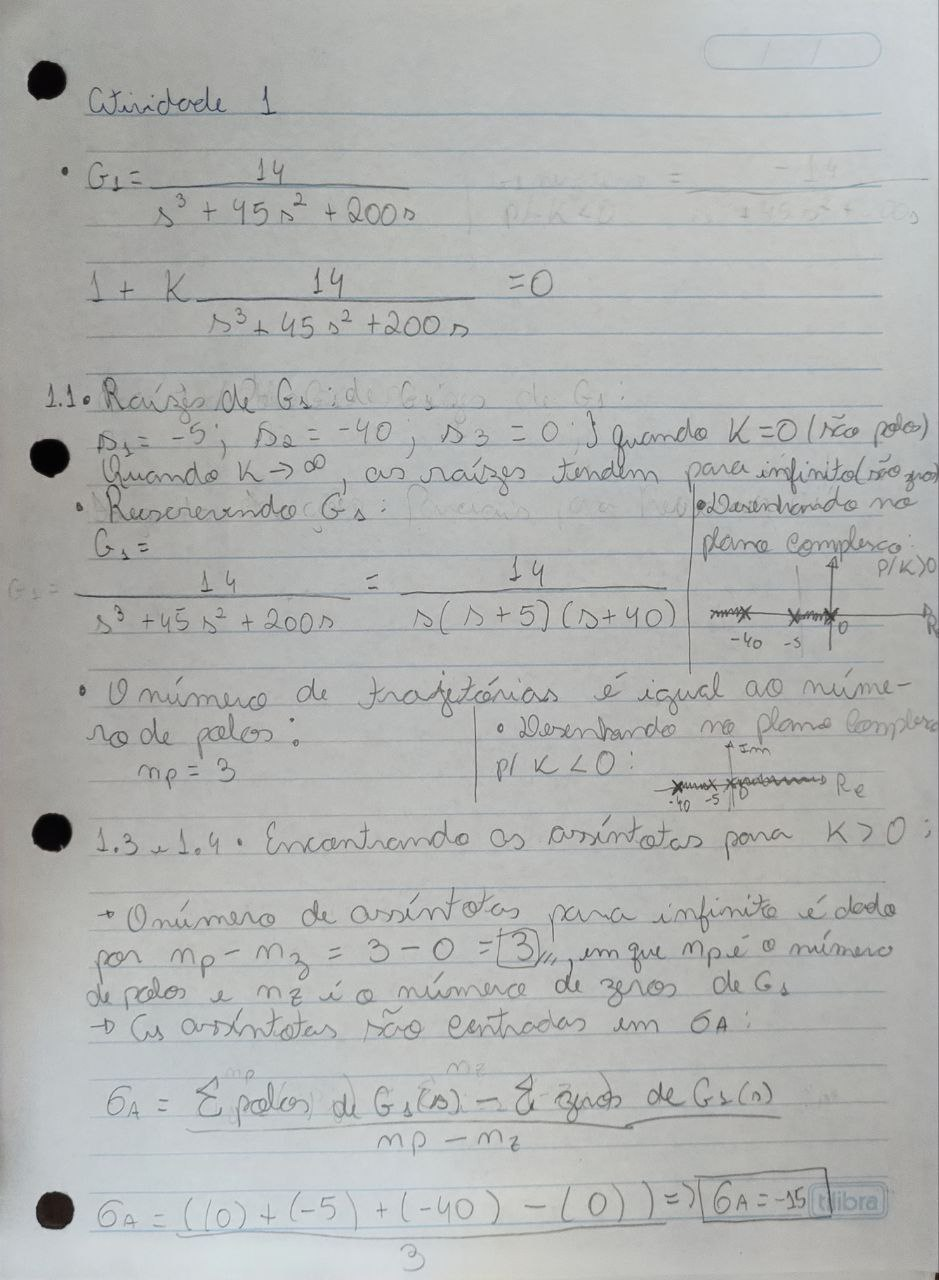

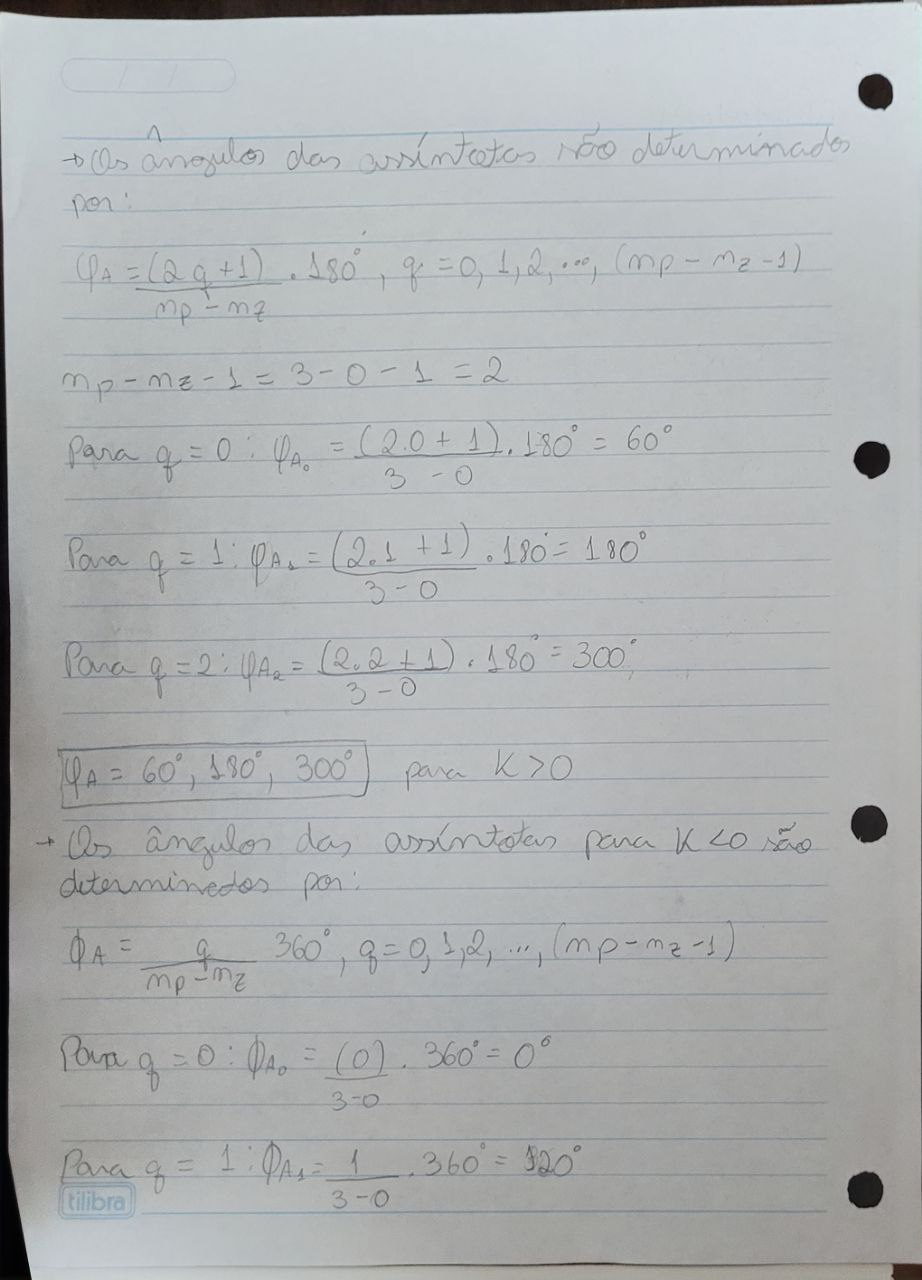

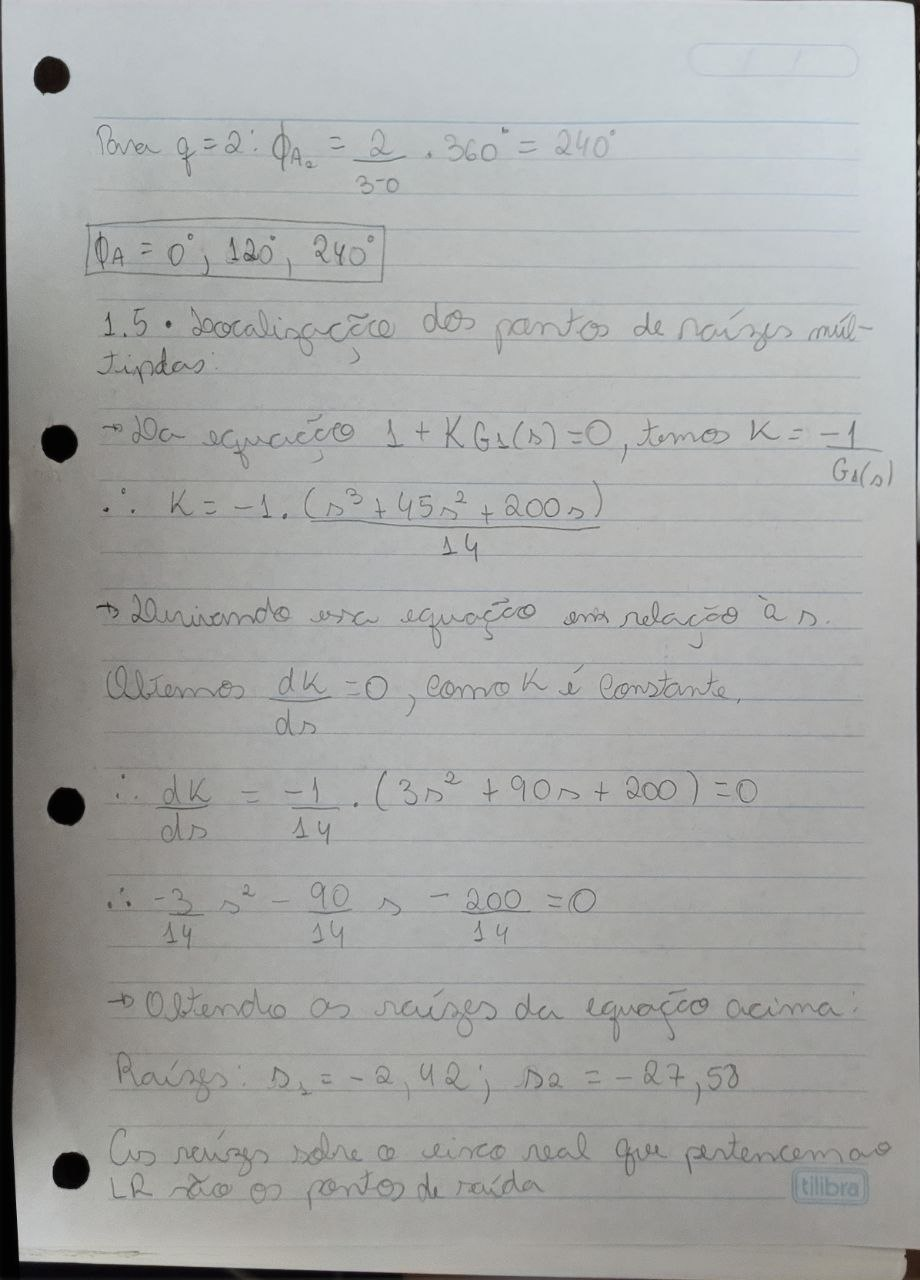

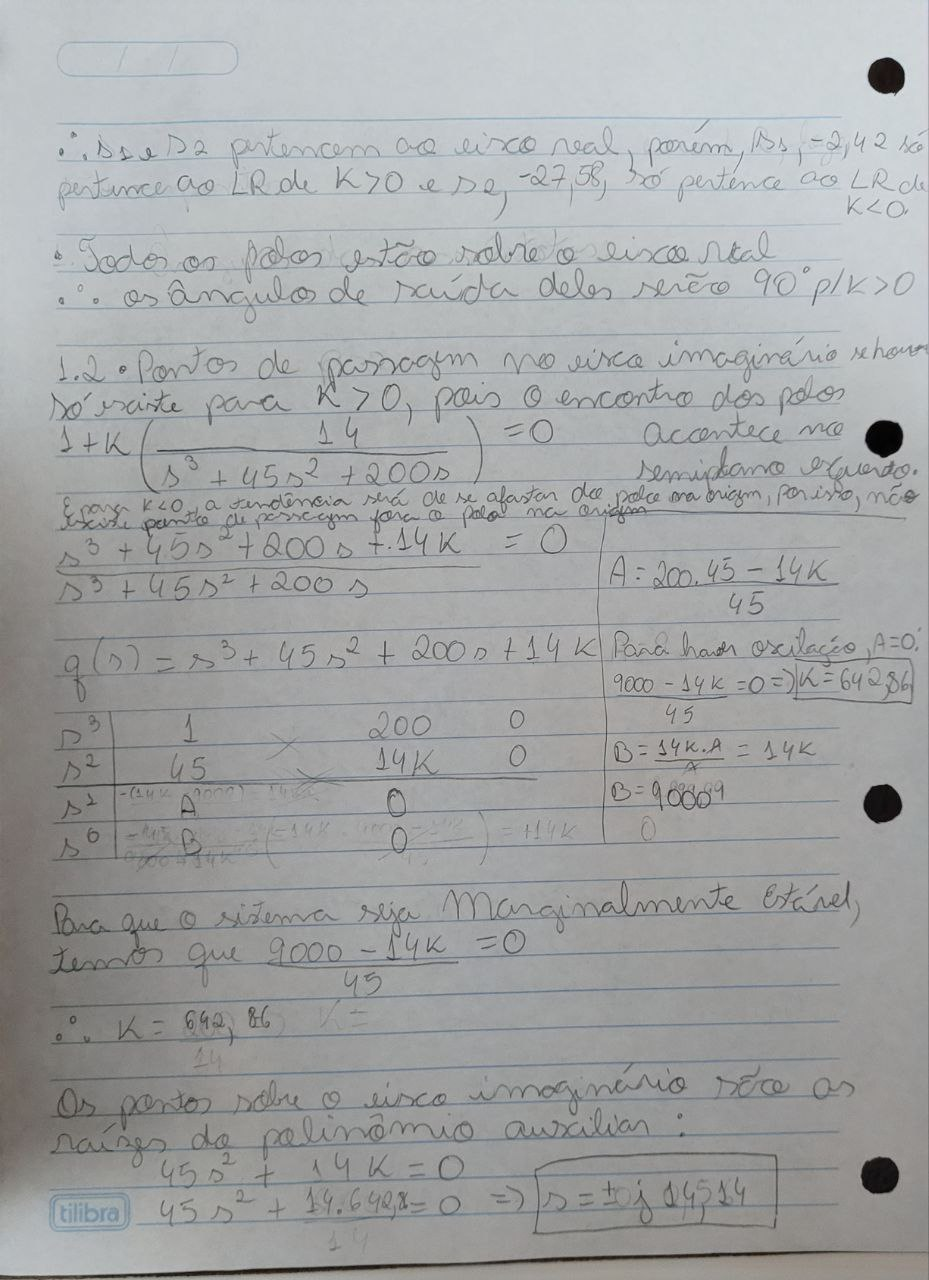

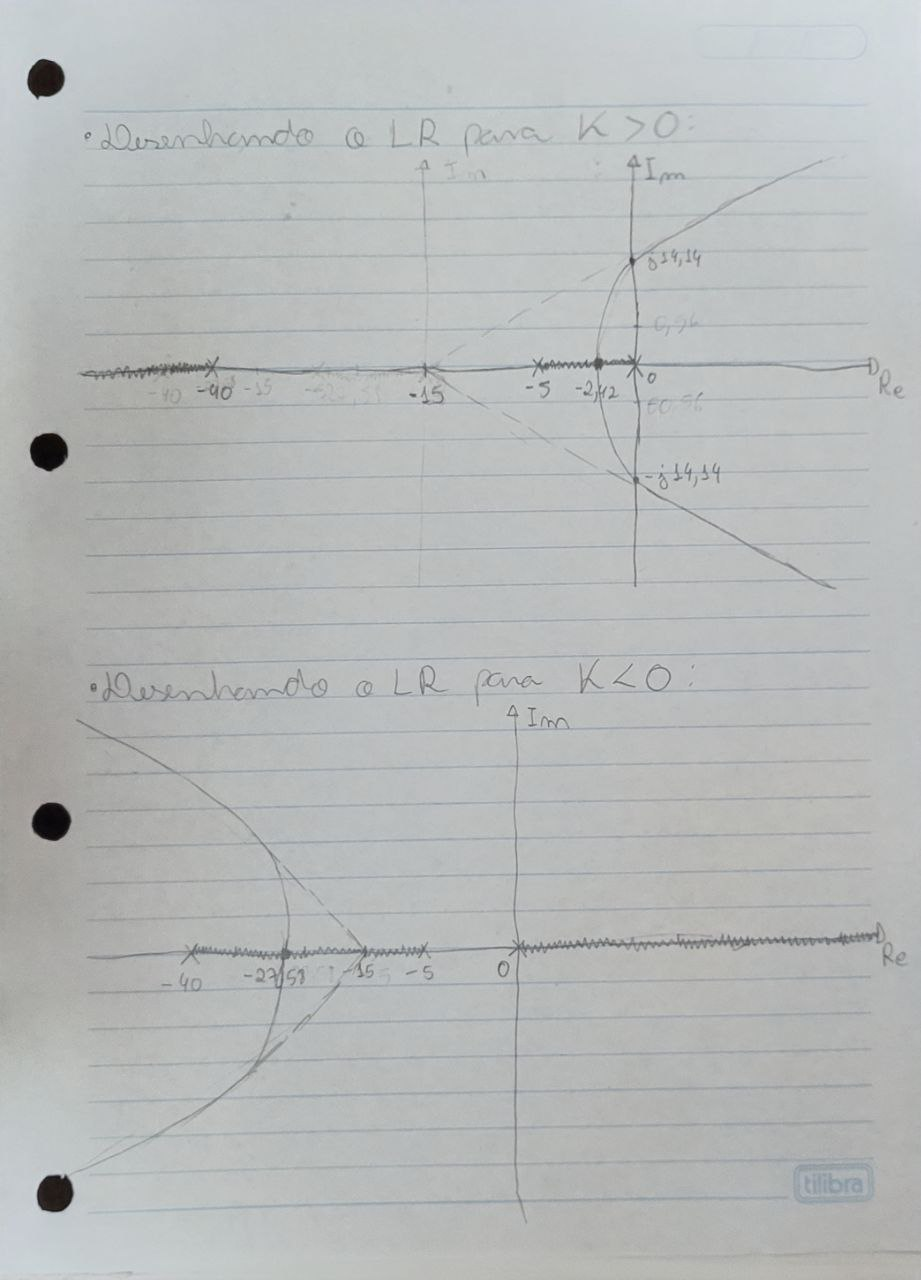

Comprovando todos os cálculos feitos, podemos ver o gráfico de G1 para K > 0 e K < 0 produzido pelo MATLAB:

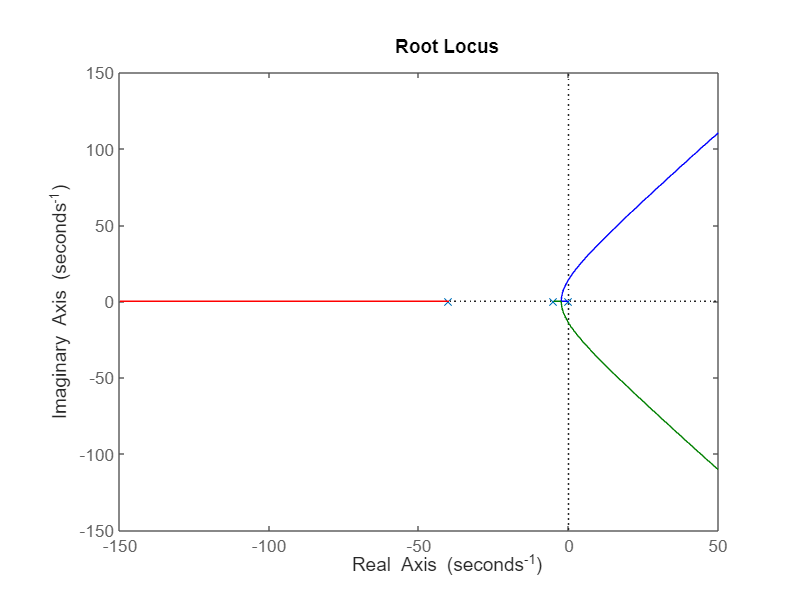

rlocus(G1)

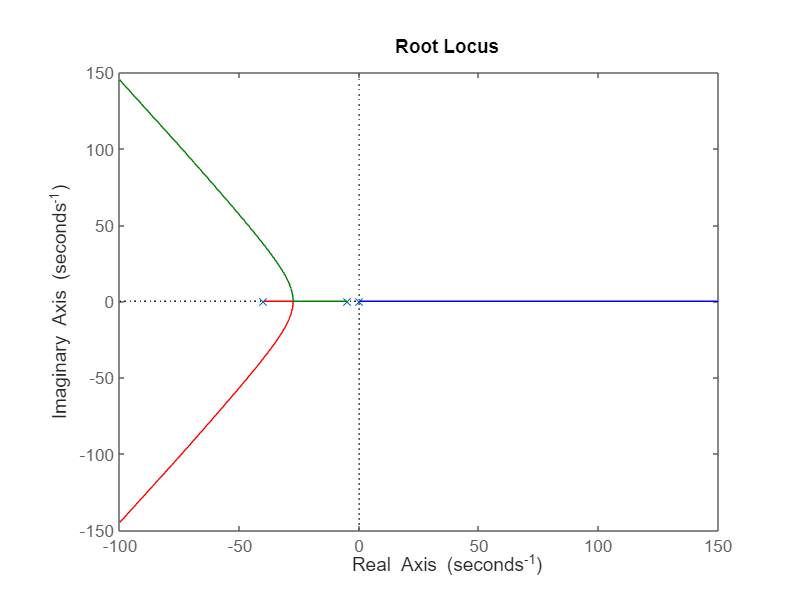

rlocus(-G1)

**Atividade 2: Seja o LR de**$1+KG_2(s)=0$** mostrado, com **$G_2$** da forma **$G_2(s)=\frac{(s+z_1)(s+z_2)...}{(s+p_1)(s+p_2)...}$**. Responder as perguntas abaixo, obtendo as informações aproximadas da figura:**

2.1 Quais são os polos e zeros de $G_2(s)$?

2.2 Quais são as raízes quando $K\longrightarrow 0$ e quando $K\longrightarrow \infty$?

2.3 Para que valores de $K>0$ e $K<0$ esse sistema é estável?

2.4 Obtenha os valores de K para os quais o par de polos complexos tem amortecimento $\zeta\geq0.707$?

2.5 Obtenha os valores de K para os quais o tempo de estabelecimento atende $t_s\leq \frac{8}{I}$.

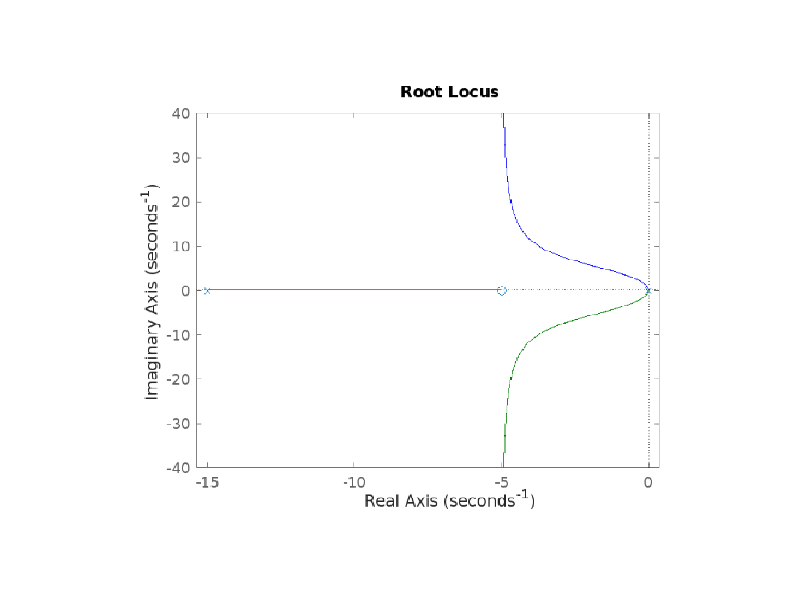

imshow('fig2.png');

Respostas:

2.1 Os polos de $G_2(s)$ são -15, 0 e 0,  zero é -5.

Portanto, temos que $G_2(s)$ é:

s=tf('s');
G2 = (s+5)/((s^2)*(s+15))

G2 =
 
     s + 5
  ------------
  s^3 + 15 s^2
 
Continuous-time transfer function.
Model Properties


2.2 As raízes quando $K\longrightarrow 0$ são os polos de G2(s), isto é, são -15, 0 e 0. Quando $K\longrightarrow \infty$ as raízes são os zeros de G2(s), isto é, -5, como pode ser observado no gráfico também.

2.3 O sistema é estável quando parte real do número é negativa. Análisando o gráfico, para qualquer valor de $K>0$ o sistema será estável.

Análisando o gráfico para $K<0$:

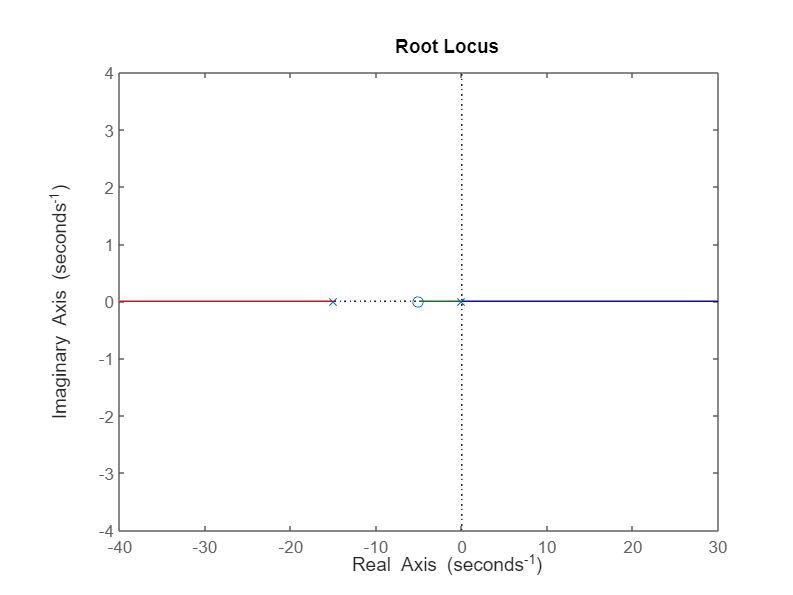

rlocus(-G2)

Para $K<0$, existe uma assíntota que se estende até o infinito no semiplano direito. Isso implica que a parte real do número nunca pode ser negativa. Portanto, para qualquer valor de $K<0$ o sistema será instável.

2.4 Verificando os valores de $K$ para os quais o par de polos complexos tem amortecimento $\zeta\geq0.707$:

rltool(G2)

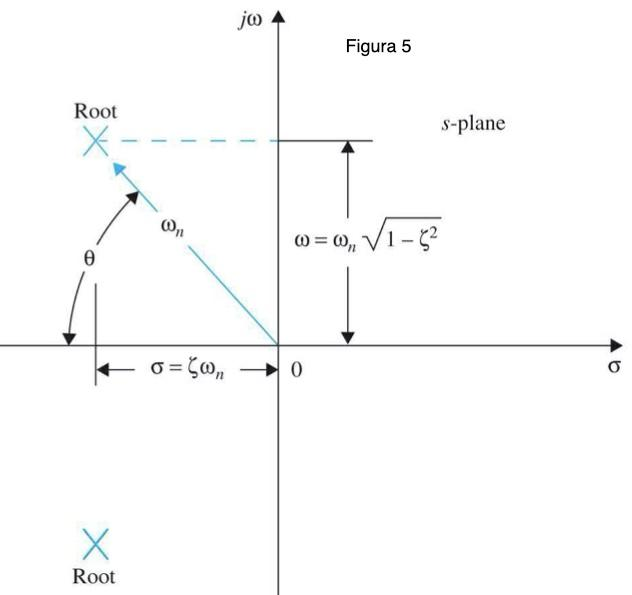

Considerando que $\zeta =\cos \;\theta$, o ângulo de 45$\degree$ corresponde a um cosseno de 0.707. Por isso, traçamos linhas que intersectam o gráfico na origem com ângulos de $\pm$45$\degree$. Como podemos observar, não há raízes complexas que se encontrem dentro da região branca restrita do gráfico com um amortecimento de 0.707; apenas as raízes só com parte real estão presentes. Portanto, não existe nenhum valor para K no qual o par de polos complexos tenha um amortecimento maior ou igual a 0.707.

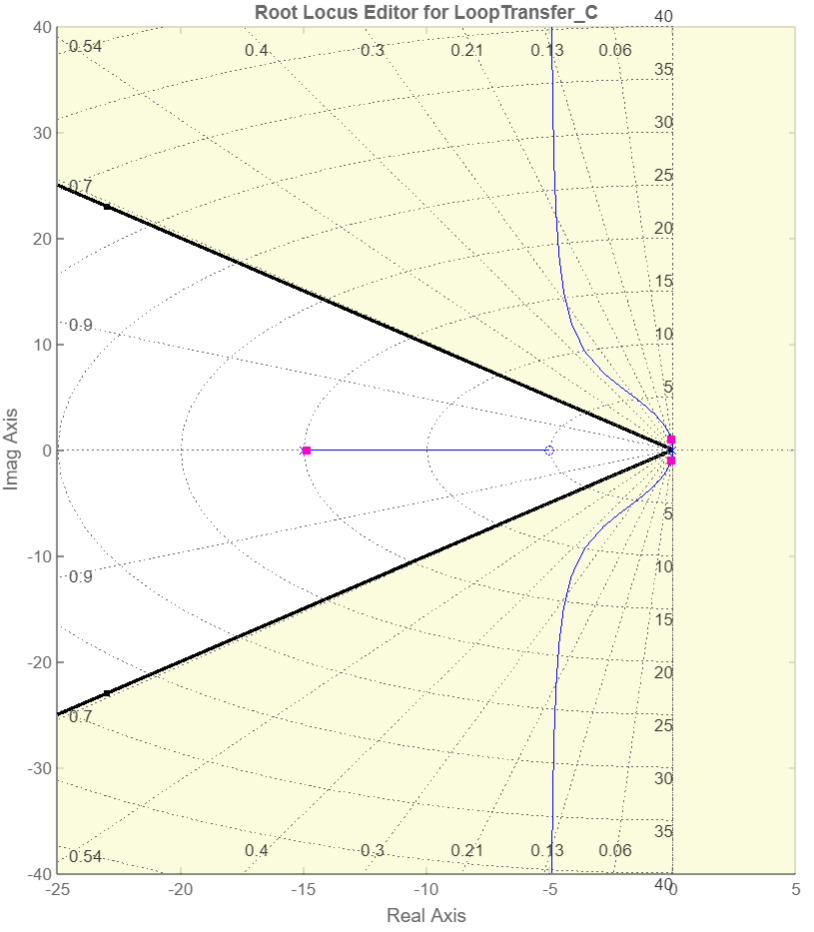

Analisando o gráfico para $K<0$, também observamos que esse valor nunca será alcançado, pois sempre teremos uma assíntota indo para o infinito positivo e uma raiz no semiplano direito.

2.5 Obtendo os valores de K para os quais o tempo de estabelecimento atende $t_s\leq \frac{8}{I}$:

ts = 8/I

ts = 0.5714

Considerando $\textrm{ts}=\frac{4}{\zeta \omega_n }$, temos: $\zeta \omega_n =\frac{4}{\textrm{ts}}$

Sabendo:

 

A parte real, que representa a distância do ponto em relação à origem para o lado esquerdo, semiplano esquerdo, é igual a  $\zeta \omega_n$.

Desejamos ter uma distância da origem para a esquerda de: 

dist_origem = 4/ts

dist_origem = 7

rltool(G2)

Portanto, os valores de K para os quais o tempo de estabelecimento de $t_s\leq 0.5714$ é atendido serão os pontos *s* que têm parte real menor ou igual que -7.

No entanto, como podemos observar na figura, as assíntotas estão indo em direção a -5. Isso significa que os polos complexos nunca terão a parte real com valor menor ou igual a -7. Eles estarão limitados a ter como valor mínimo da parte real -5. Apenas o polo real poderia ter um valor menor ou igual a -7.  Portanto, não existe nenhum valor para K para que o  tempo de estabelecimento atende $t_s\leq 0.5714$

O gráfico abaixo confirma essa análise:

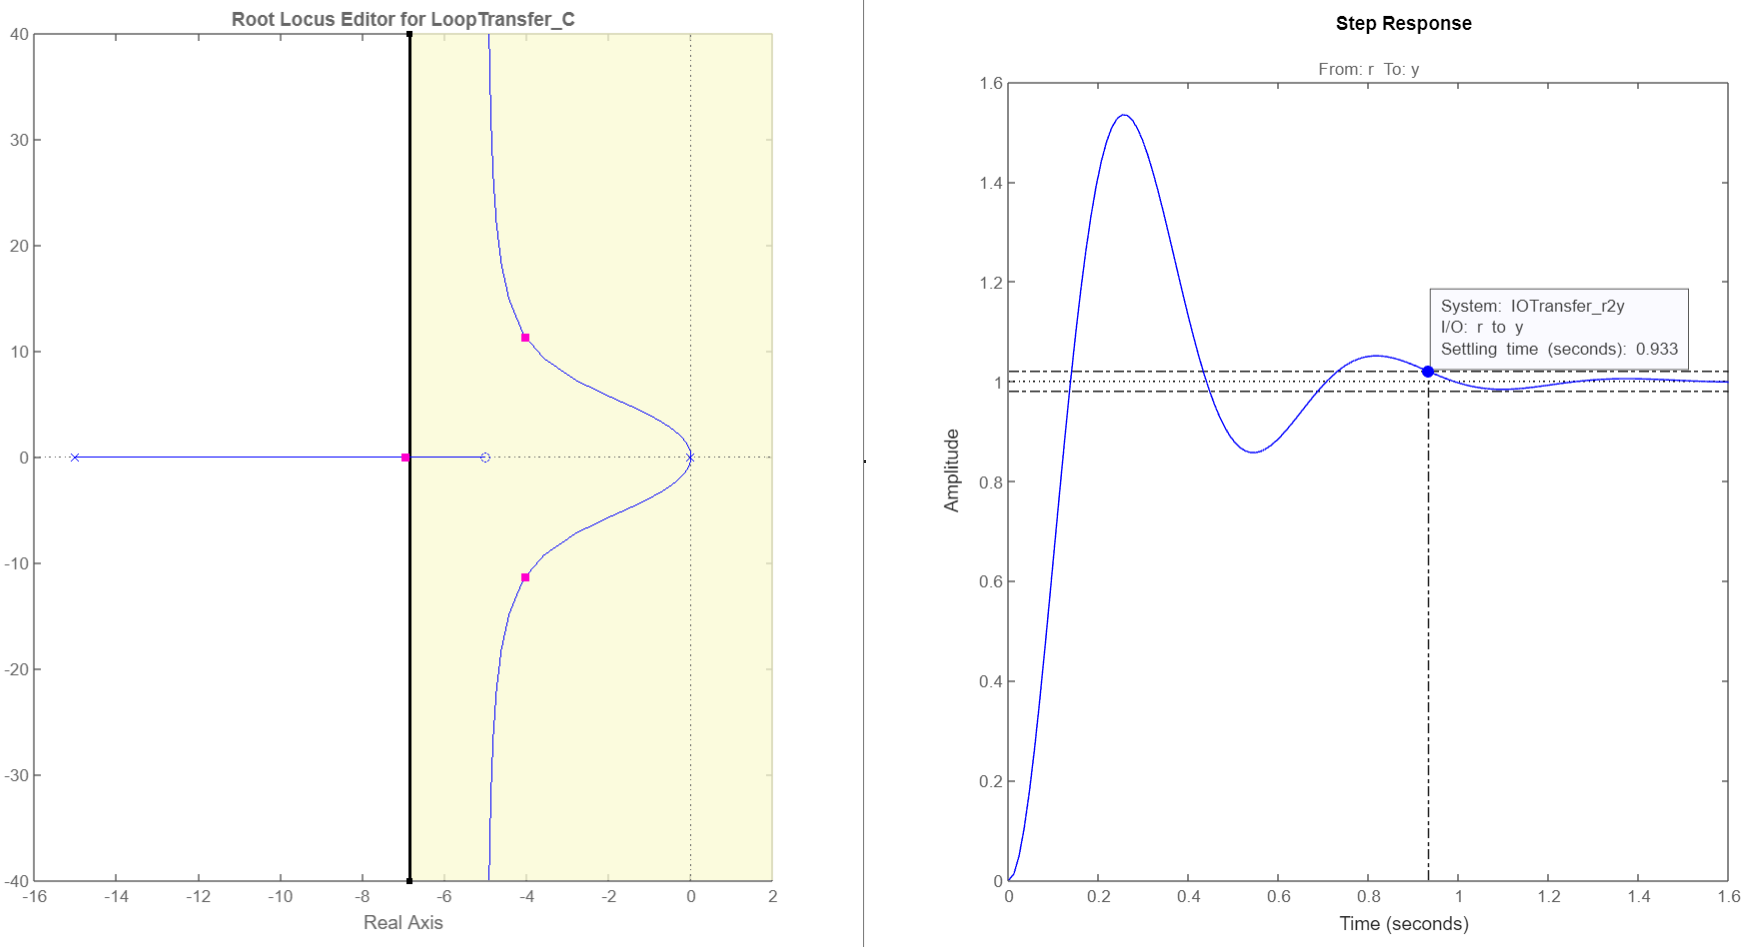

Analisando o gráfico para $K<0$, também observamos que esse valor nunca será alcançado, pois sempre teremos uma assíntota indo para o infinito positivo e uma raiz no semiplano direito.

**Atividade 3: Seja a FT de primeira ordem com tempo morto **$G_3(s)$**. Discretize esta FT obtendo **$G_3(z)$** com tempo de amostragem igual a 1/5 do tempo morto, faça o LR discreto e responda as perguntas abaixo:**

3.1 Identifique os polos e zeros  de $G_3(z)$.

3.2 Obtenha todos os valores de $K\in[-\infty, \infty]$para os quais este sistema é estável.

3.3 Para que valores de K tem-se $UP\leq10\%$?

3.4 Verifique se existem valores de K para os quais $t_s\leq 10I$s.

G3

G3 =
 
                  8
  exp(-10*s) * --------
               40 s + 1
 
Continuous-time transfer function.
Model Properties


Discretize esta $G_3(s)$ para obter $G_3(z)$:

tempo_morto = 10

tempo_morto = 10

tempo_amostragem = (1/5)*tempo_morto

tempo_amostragem = 2

s = tf('s');
G3_sem_tempo_morto = 8/((40*s)+1)

G3_sem_tempo_morto =
 
     8
  --------
  40 s + 1
 
Continuous-time transfer function.
Model Properties


G3_z_sem_tempo_morto = c2d(G3_sem_tempo_morto, tempo_amostragem)

G3_z_sem_tempo_morto =
 
    0.3902
  ----------
  z - 0.9512
 
Sample time: 2 seconds
Discrete-time transfer function.
Model Properties


Discretizando o atraso:

atraso = tempo_morto/tempo_amostragem

atraso = 5

Dado um tempo morto de 10 segundos e um intervalo de amostragem de 2 segundos, podemos observar que os 10 segundos de tempo morto equivalem a 5 intervalos de amostragem.

Portanto, precisamos multiplicar nossa função de transferência $G_3(z)$ que não considera o tempo morto por $z^{-5}$.

z = tf('z', tempo_amostragem);
G3z = G3_z_sem_tempo_morto*z^(-atraso)

G3z =
 
       0.3902
  ----------------
  z^6 - 0.9512 z^5
 
Sample time: 2 seconds
Discrete-time transfer function.
Model Properties


3.1 Identificando os polos e zeros  de $G_3(z)$:

Conforme pode ser observado na função acima e no gráfico abaixo, *G*3(*z*) não possui zeros e possui 3 polos em zero, além de outro polo em +0.9512.

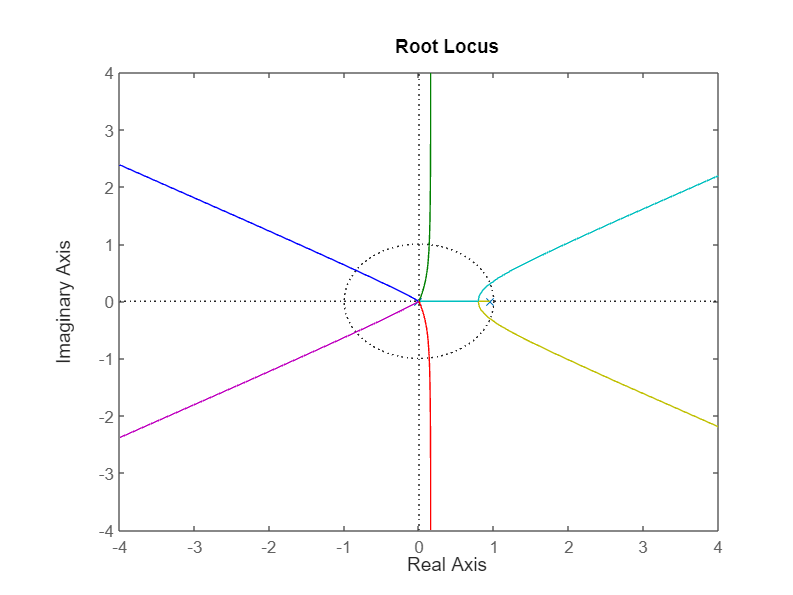

rlocus(G3z)

3.2 Obtendo todos os valores de $K\in[-\infty, \infty]$ para os quais este sistema é estável:

Para K > 0, temos:

Um sistema discreto é considerado marginalmente estável se ele possui pelo menos um polo na circunferência do círculo unitário (ou seja, tem um polo com módulo igual a 1). Neste caso, as soluções podem oscilar.

Portanto, vamos utilizar a função `rltool` na função de transferência discreta e posicionar o primeiro polo sobre o círculo unitário. Isso fará com que a resposta, que antes era estável, se torne instável. Em seguida, determinaremos o primeiro valor de *K* que a função pode ter para se tornar instável:

%rltool(G3z)

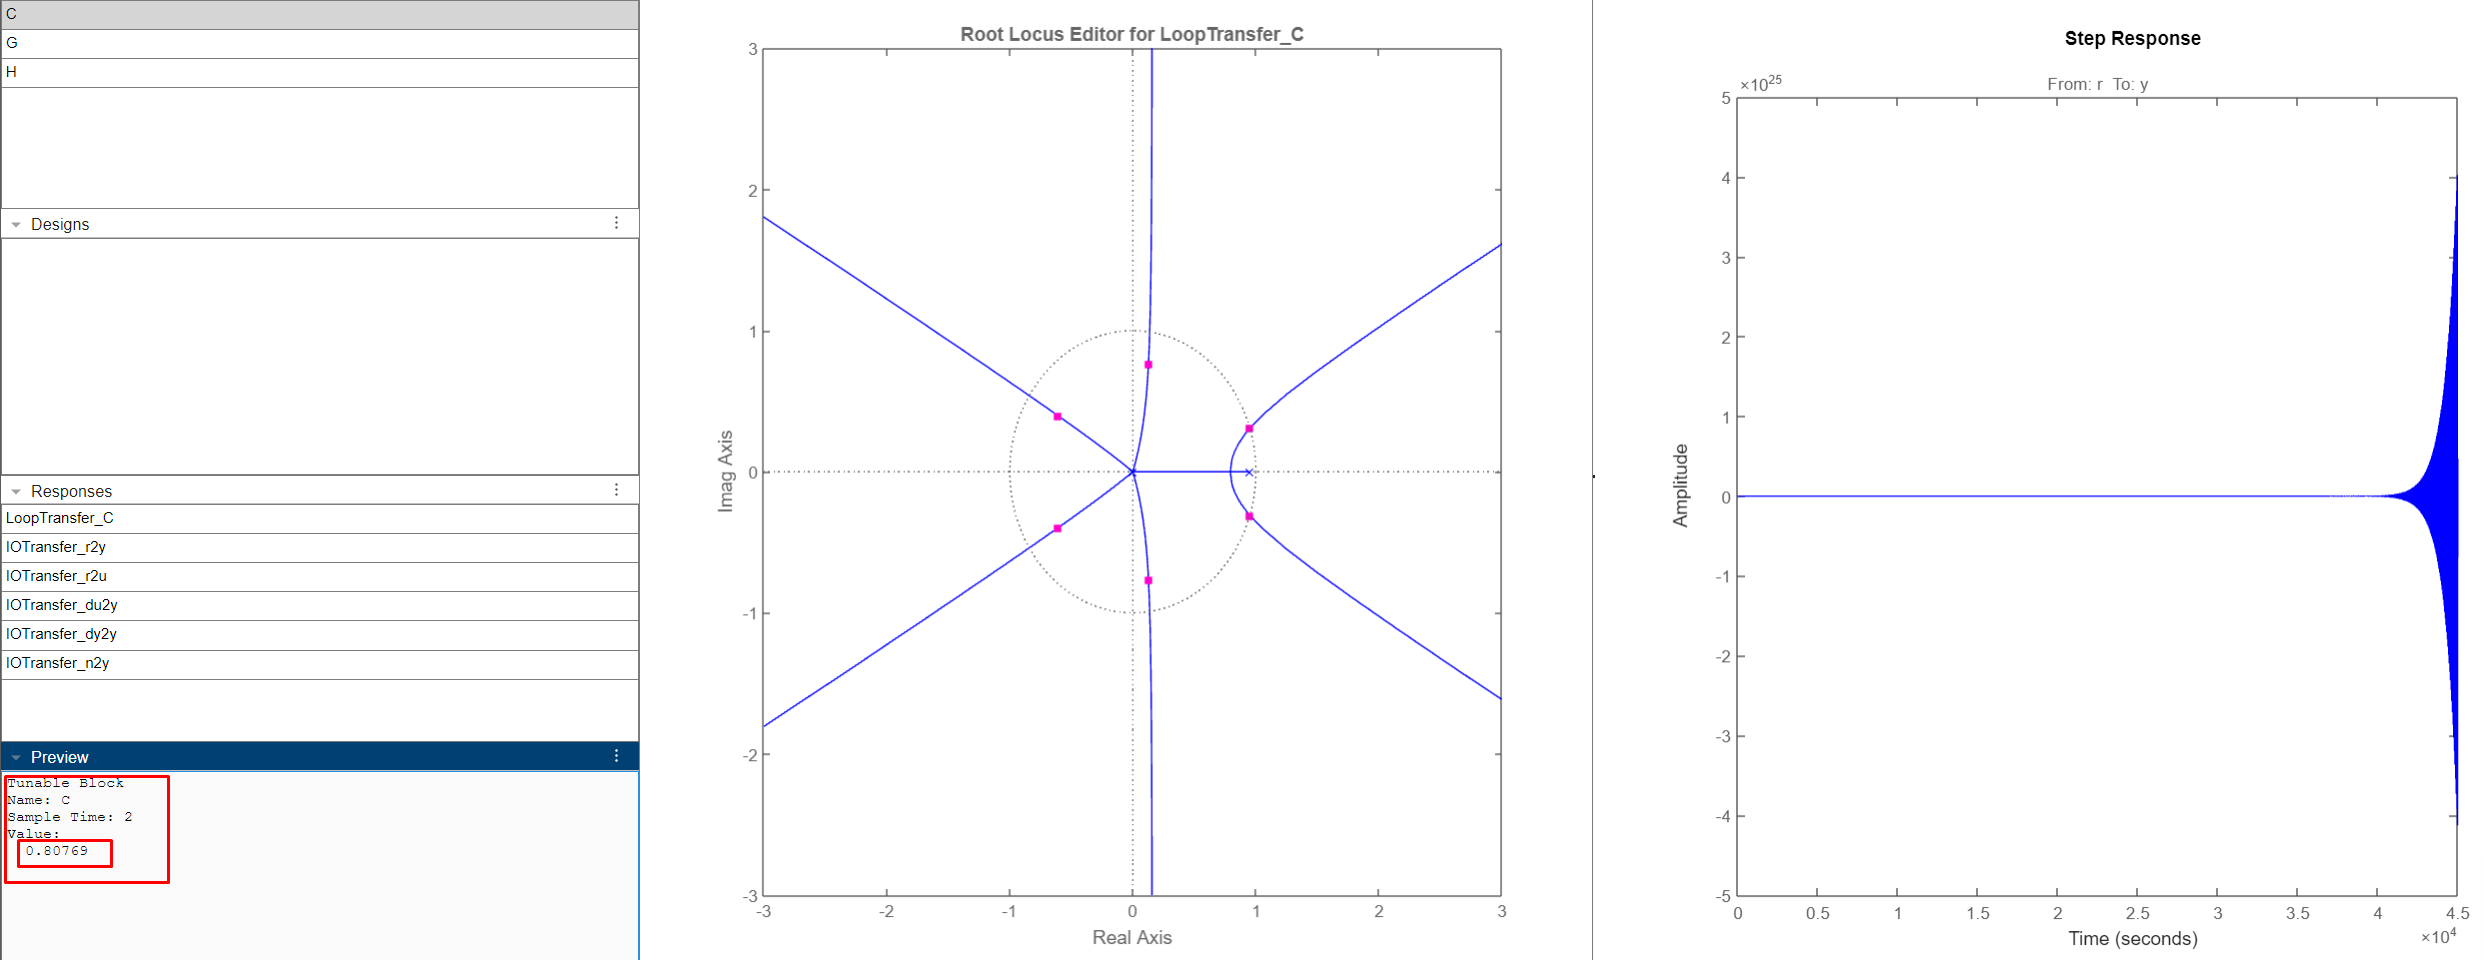

Como pode ser observado acima, quando os polos do lado direito estão sobre o círculo unitário, *K* assume um valor de 0.8 e a resposta se torna instável.

Portanto, *K* precisa ser menor que 0.8 para garantir a estabilidade. Um exemplo está demonstrado abaixo com *K*=0.73, o qual é próximo a 0.8. Com este valor de *K*, o sistema se estabiliza. 

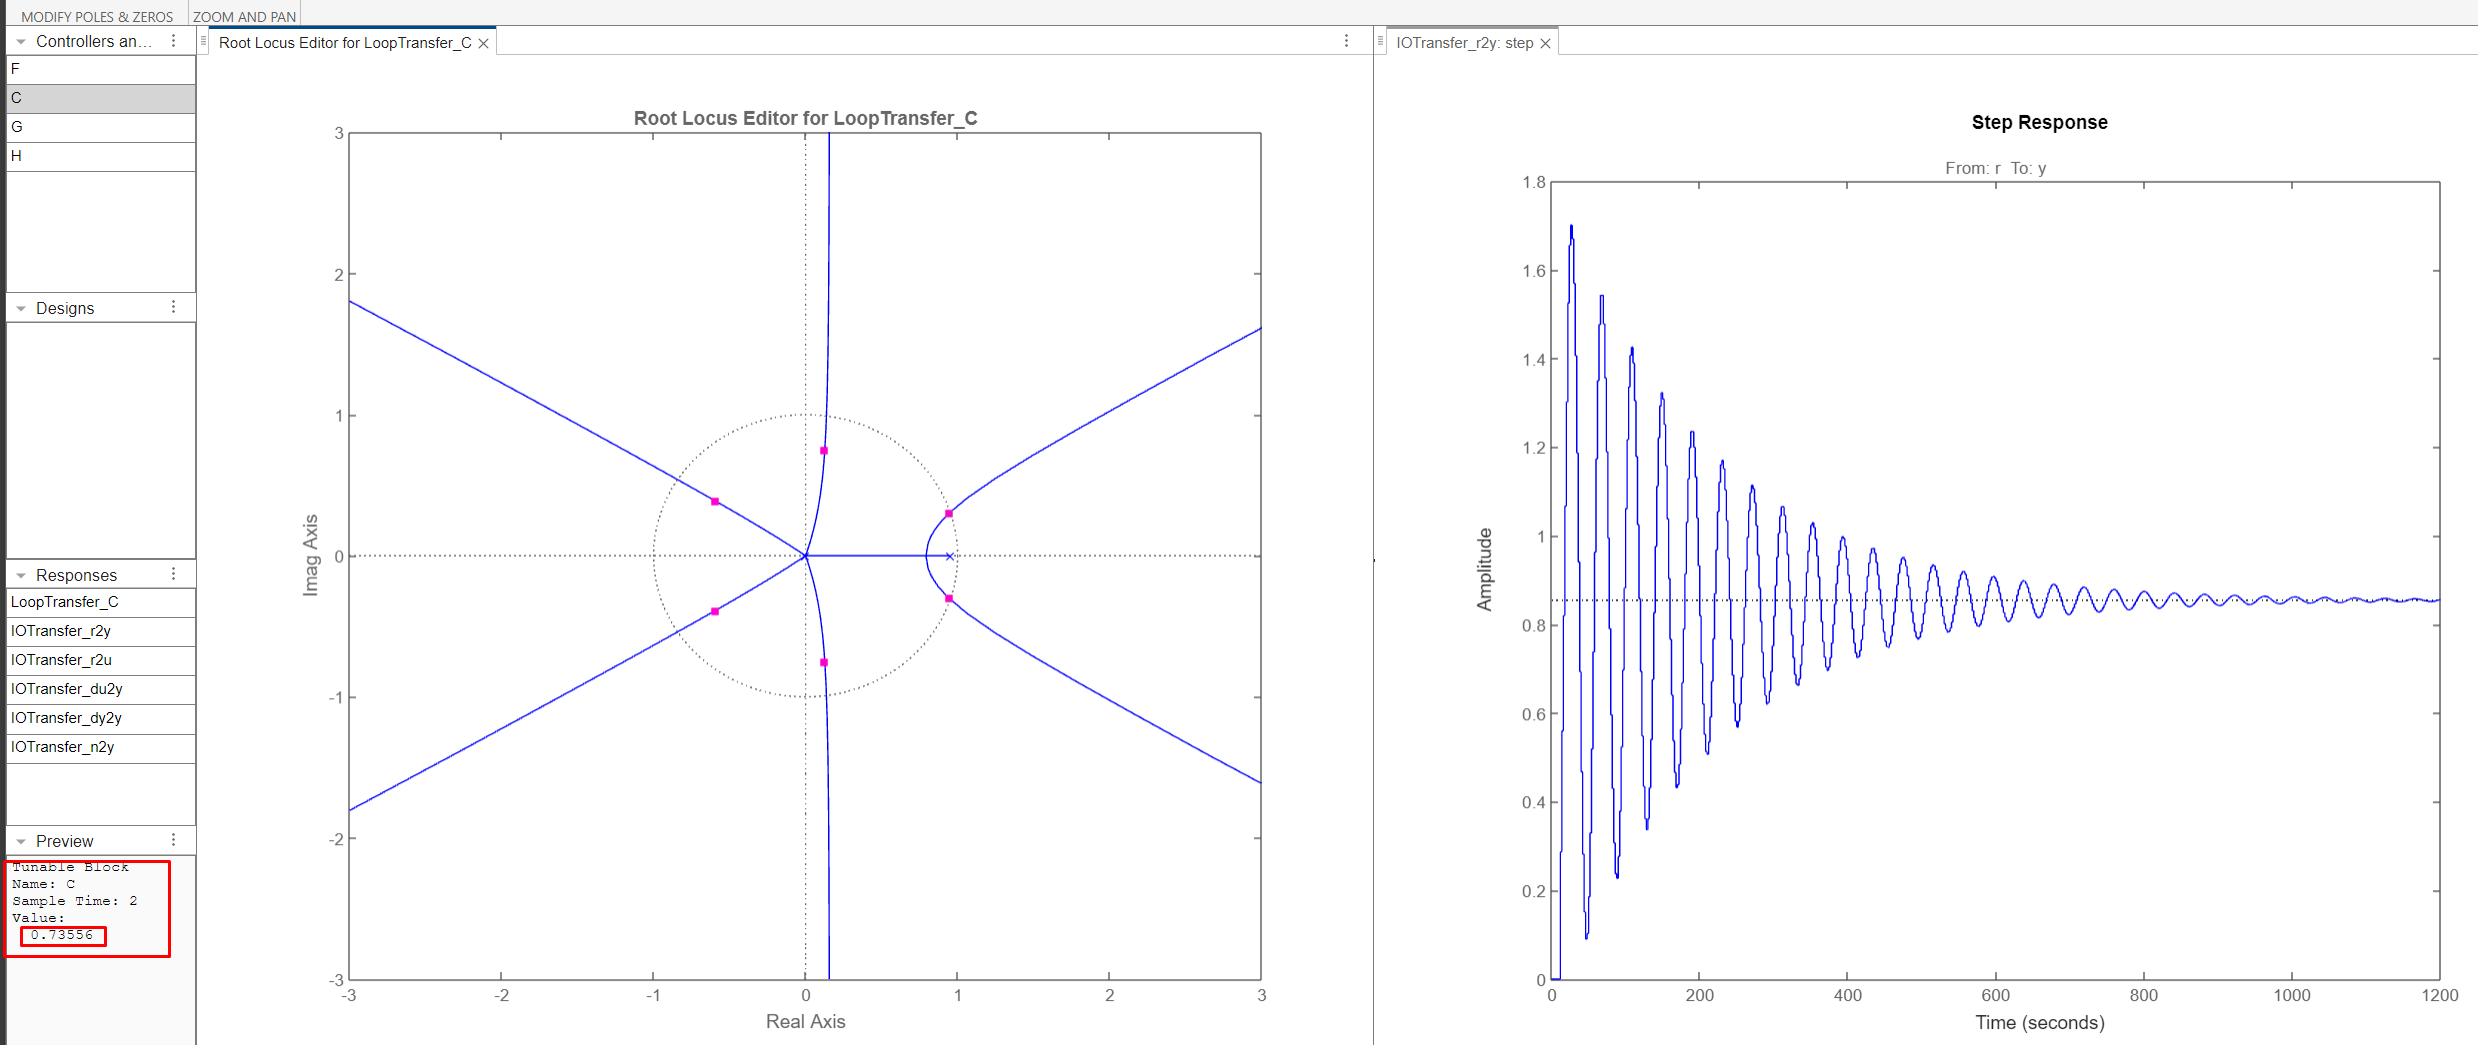

Dessa forma, é de fato essencial que *K* seja inferior a 0.8 para manter a estabilidade do sistema.

Outro método para encontrar o valor de *K* seria observar o gráfico gerado pela função `rlocus` aplicada a G3(z) e verificar os primeiros pontos que tocam o círculo unitário. Isso resultará em uma resposta instável e em no menor K que torna a resposta instável.

rlocus(G3z)

Podemos observar que os pontos à direita, que são aqueles que primeiro alcançam a circunferência unitária, os mais lentos, assumem valores de 0.95 ± *j*0.31  quando estão sobre ela.

Como $1+KG_3(z)=0$, logo $K=-1/G_3(z)$

K_func = -1/G3z

K_func =
 
  -z^6 + 0.9512 z^5
  -----------------
       0.3902
 
Sample time: 2 seconds
Discrete-time transfer function.
Model Properties


z_inst = 0.95 + 0.31i;
K_calc = (-(z_inst^6) + (0.9512*(z_inst^5)))/(0.3902)

K_calc = 0.7917 + 0.0081i

K = evalfr(K_func, z_inst)

K = 0.7917 + 0.0081i

Portanto, quando os polos do lado direito estão sobre o círculo unitário, calculamos que *K* assume um valor de 0.79 que é muito próximo de 0.8, valor encontrado no método anterior, e a resposta se torna instável.

Confirmando que *K* precisa ser menor que 0.79 para garantir a estabilidade.

Para K < 0, temos:

Como já explicado, um sistema discreto é considerado marginalmente estável se ele possui pelo menos um polo na circunferência do círculo unitário (ou seja, tem um polo com módulo igual a 1). Neste caso, as soluções podem oscilar.

Portanto, vamos utilizar a função `rltool` na função de transferência discreta e posicionar o primeiro polo sobre o círculo unitário. Isso fará com que a resposta, que antes era estável, se torne instável. Em seguida, determinaremos o primeiro valor de *K* que a função pode ter para se tornar instável:

%rltool(-G3z)

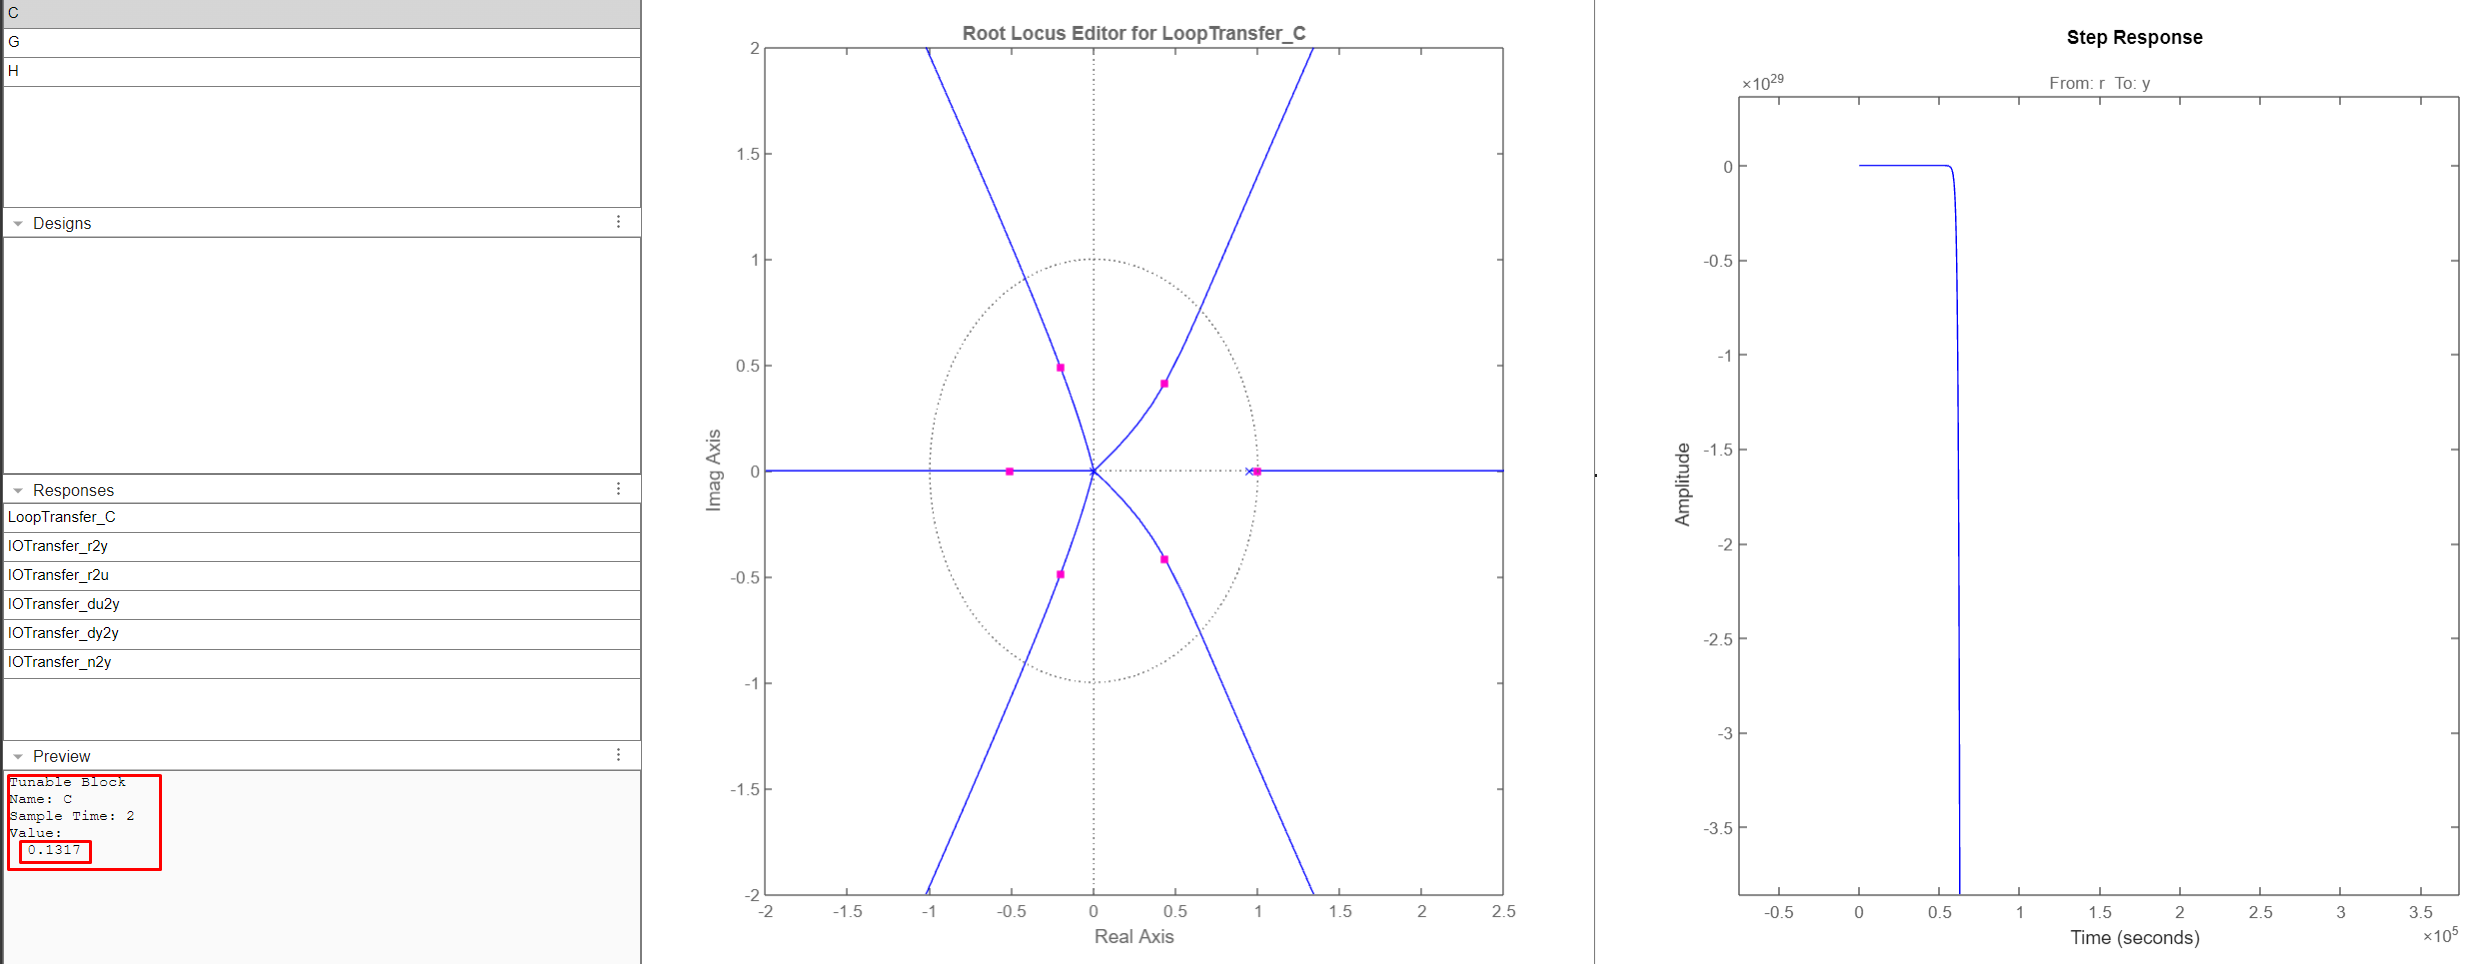

Como pode ser observado acima, quando o polo do lado direito está sobre o círculo unitário, *K* assume um valor de -0.13 e a resposta se torna instável.

Portanto, *K* precisa ser maior que -0.13 para garantir a estabilidade. Um exemplo está demonstrado abaixo com *K*= -0.1239, o qual é próximo a -0.13. Com este valor de *K*, o sistema se estabiliza. 

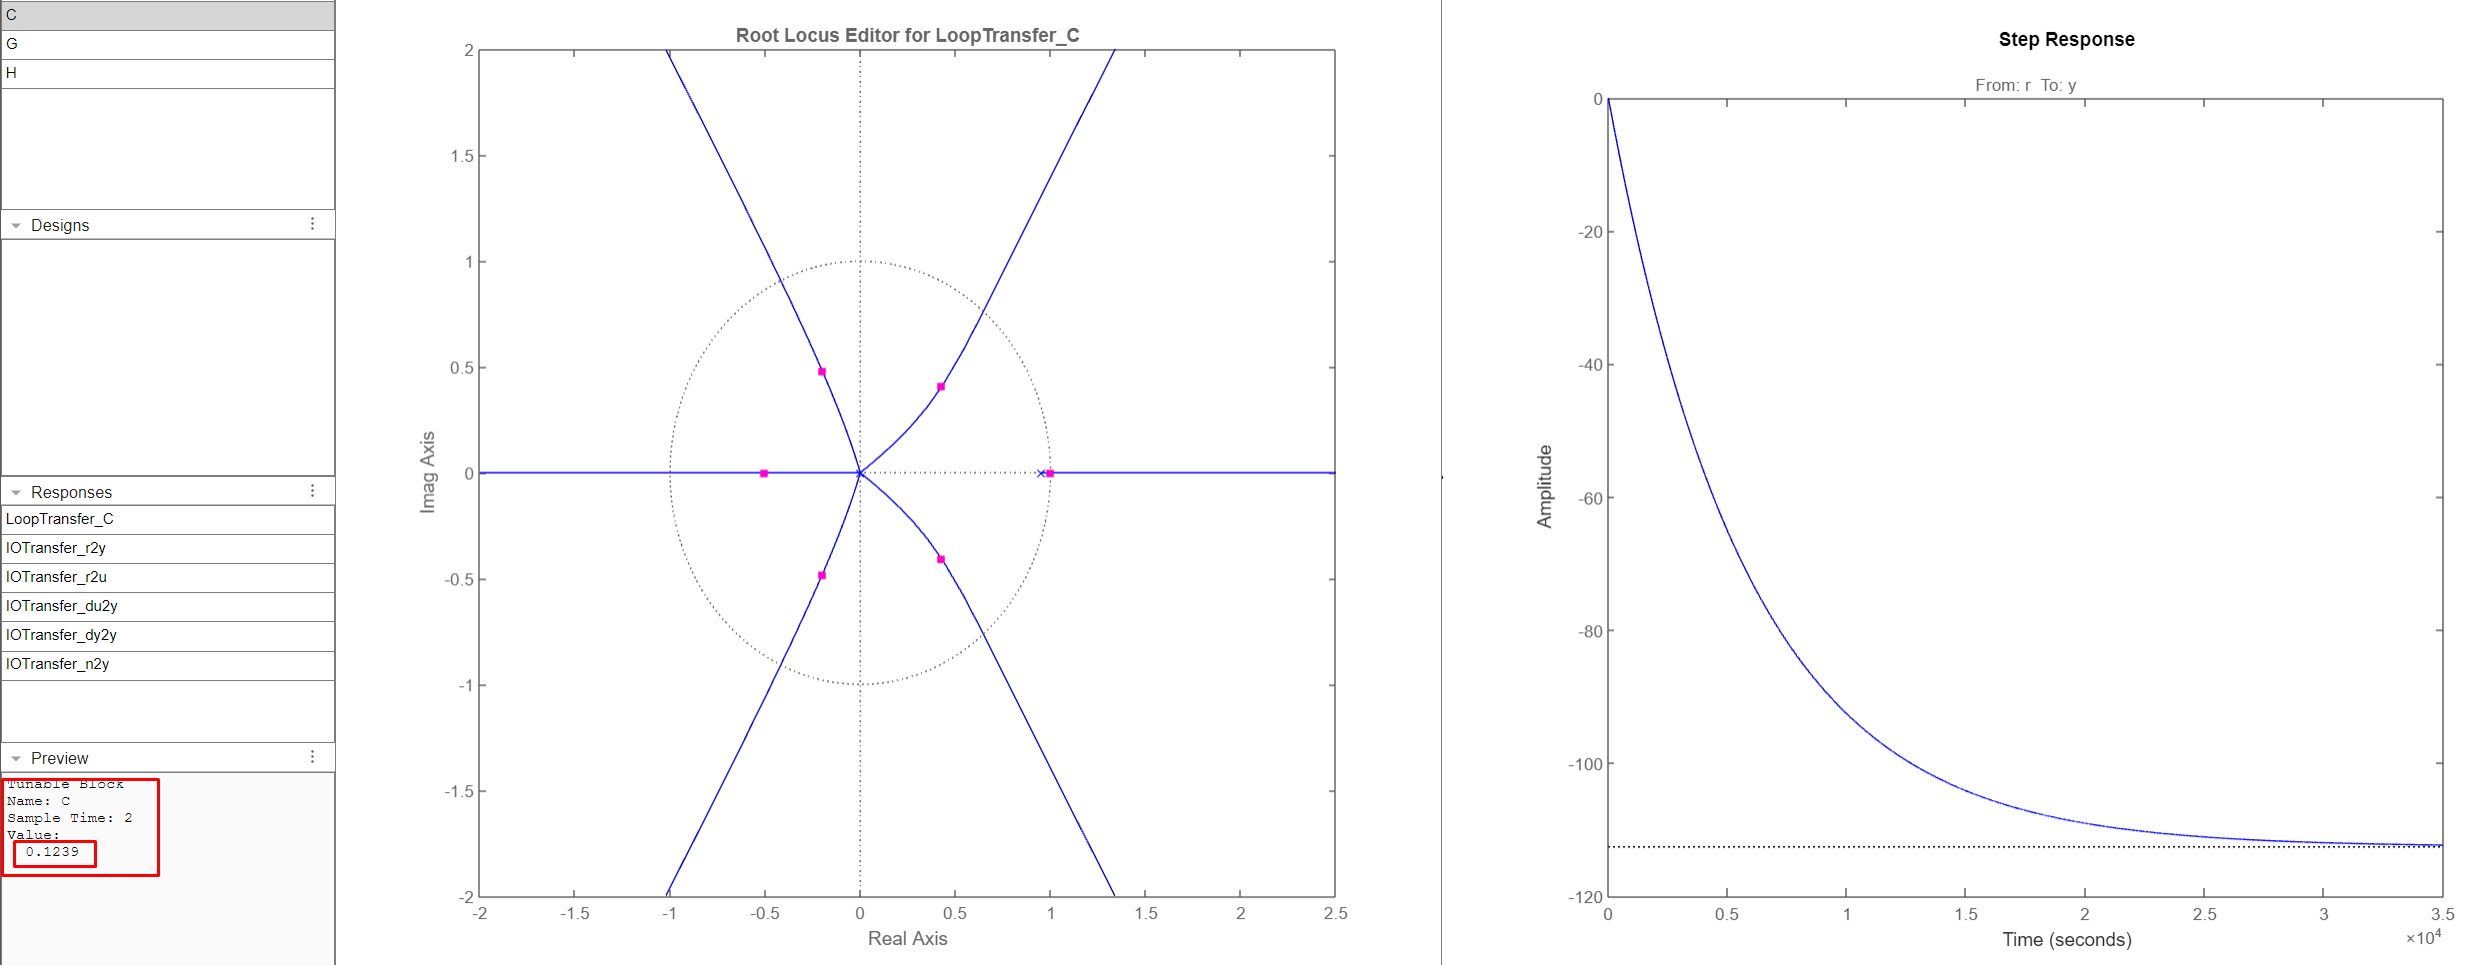

Dessa forma, é de fato essencial que *K* seja maior que -0.13 para manter a estabilidade do sistema.

Outro método para encontrar o valor de *K* seria observar o gráfico gerado pela função `rlocus` aplicada a G3(z) e verificar os primeiros pontos que tocam o círculo unitário. Isso resultará em uma resposta instável e em no menor K que torna a resposta instável.

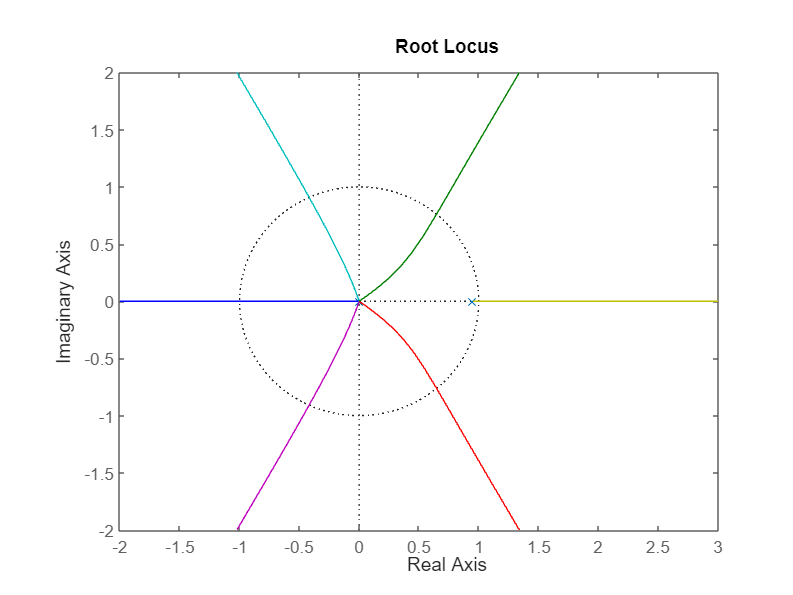

rlocus(-G3z)

Podemos observar que o ponto à direita, que é aqueles que primeiro alcançam a circunferência unitária, o mais lento, assumem valores de 1  quando está sobre ela.

Como $1-KG_3(z)=0$, logo $K=1/G_3(z)$

K_func = 1/G3z

K_func =
 
  z^6 - 0.9512 z^5
  ----------------
       0.3902
 
Sample time: 2 seconds
Discrete-time transfer function.
Model Properties


z_inst = 1;
K_calc = ((z_inst^6) - (0.9512*(z_inst^5)))/(0.3902)

K_calc = 0.1251

K = evalfr(K_func, z_inst)

K = 0.1250

Portanto, quando o polo do lado direito está sobre o círculo unitário, calculamos que *K* assume um valor de -0.1250 que é muito próximo de -0.13, valor encontrado no método anterior, e a resposta se torna instável.

Confirmando que *K* precisa ser maior que -0.1250 para garantir a estabilidade.

3.3 Valores de K em que $UP\leq10\%$:

Para K > 0, temos:

Vamos utilizar a função `rltool` na função de transferência discreta e adicionar como requisito que o UP seja menor ou igual a 10%. Como podemos observar, as últimas raizes que estão na região branca restrita do gráfico têm UP menor ou igual a 10%. 

Para encontrar o maior valor de K que apresente esse requisito, vamos posicionar os últimos polos bem próximo da borda. Isso fará com que a resposta, que antes tinha UP menor ou igual a 10%, não tenha mais. Em seguida, determinaremos o primeiro valor de *K* que a função pode ter para ter UP maior do que 10%:

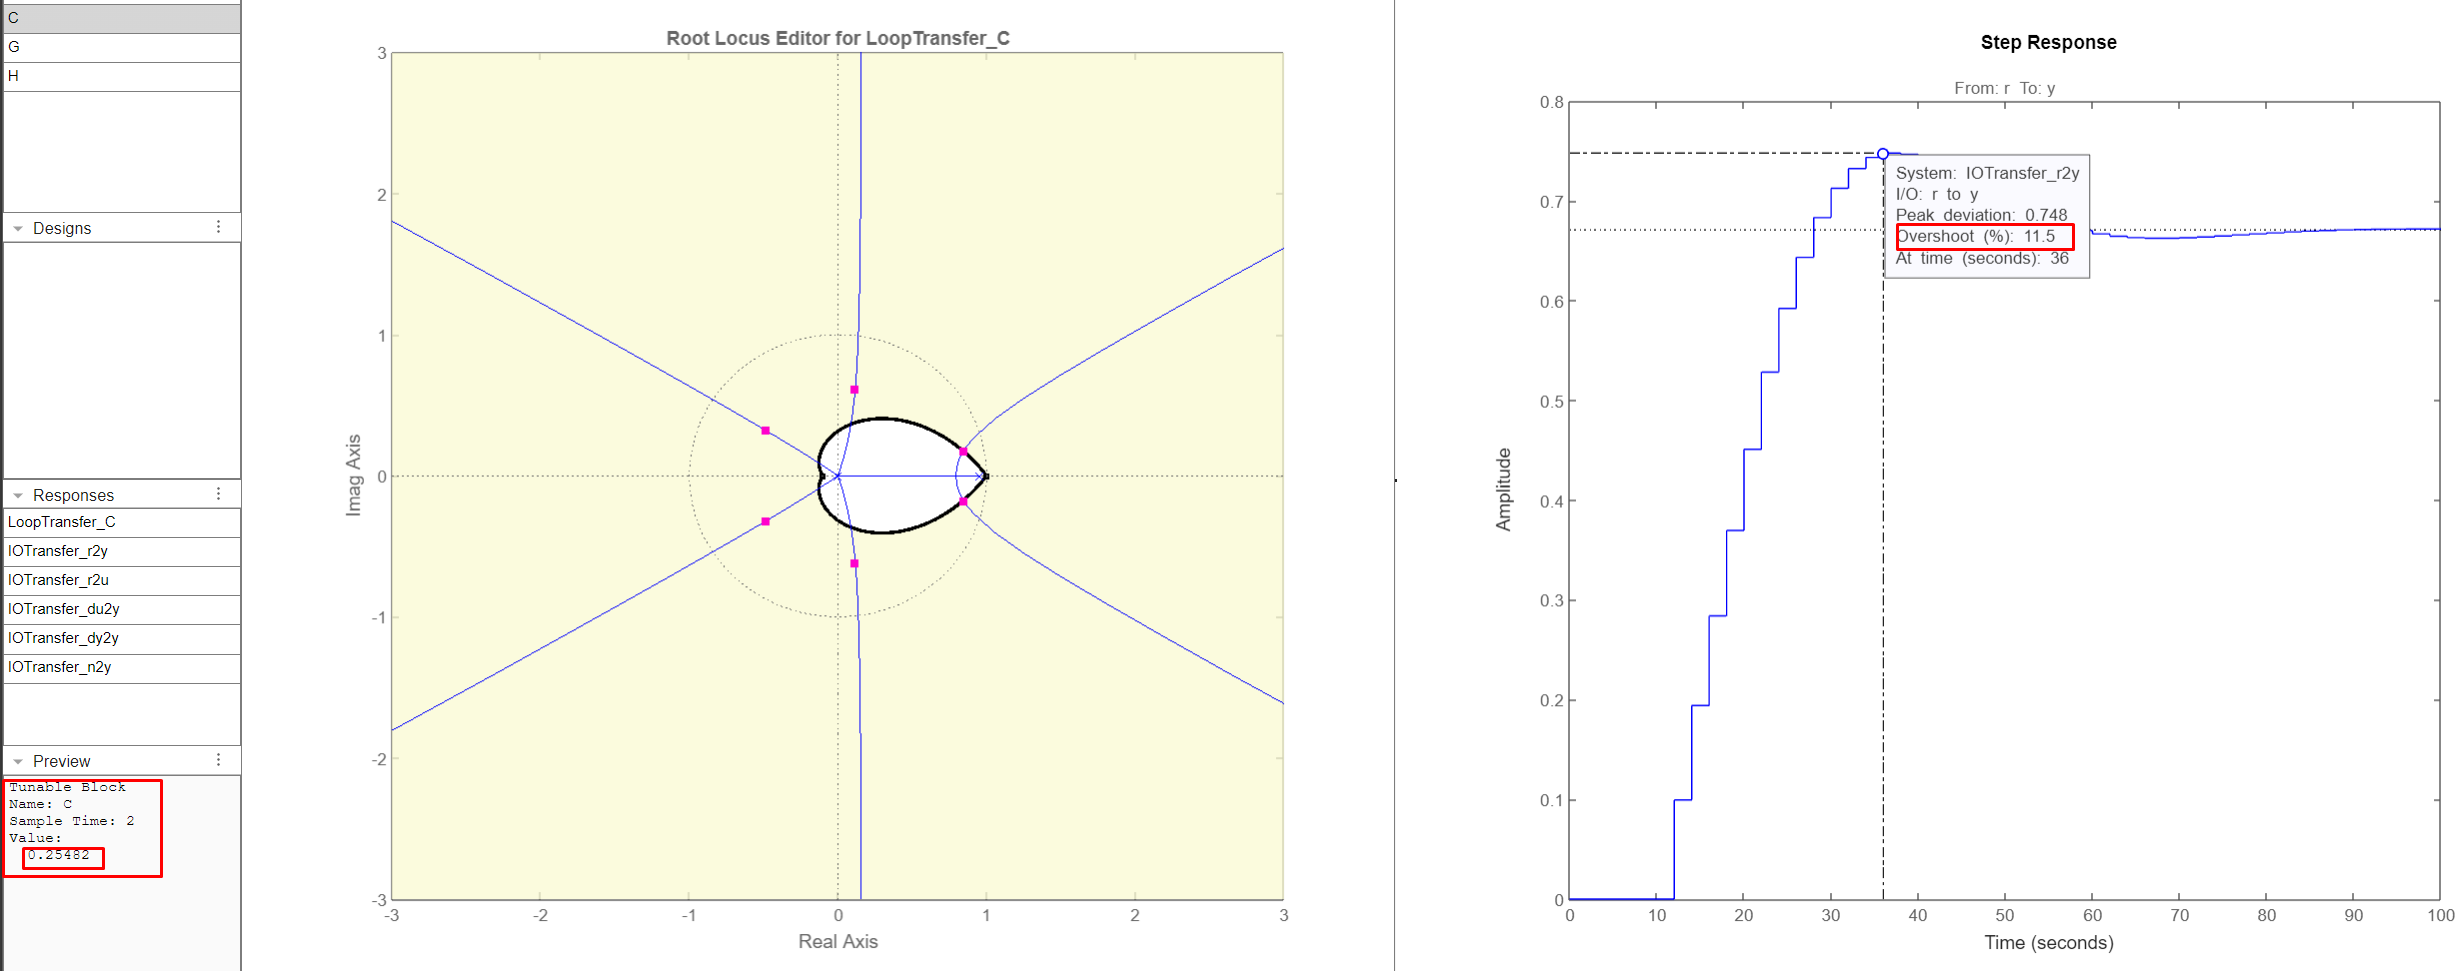

Como pode ser observado acima, quando os polos do lado direito está sobre a área definida, *K* assume um valor de 0.25 e a resposta tem um UP de 11.5% que é maior que 10%.

Portanto, *K* precisa ser menor que 0.25 para ter um UP menor que 10%. Um exemplo está demonstrado abaixo com *K*= 0.22, o qual é próximo a 0.25. Com este valor de *K*, o tem um UP menor que 10%. 

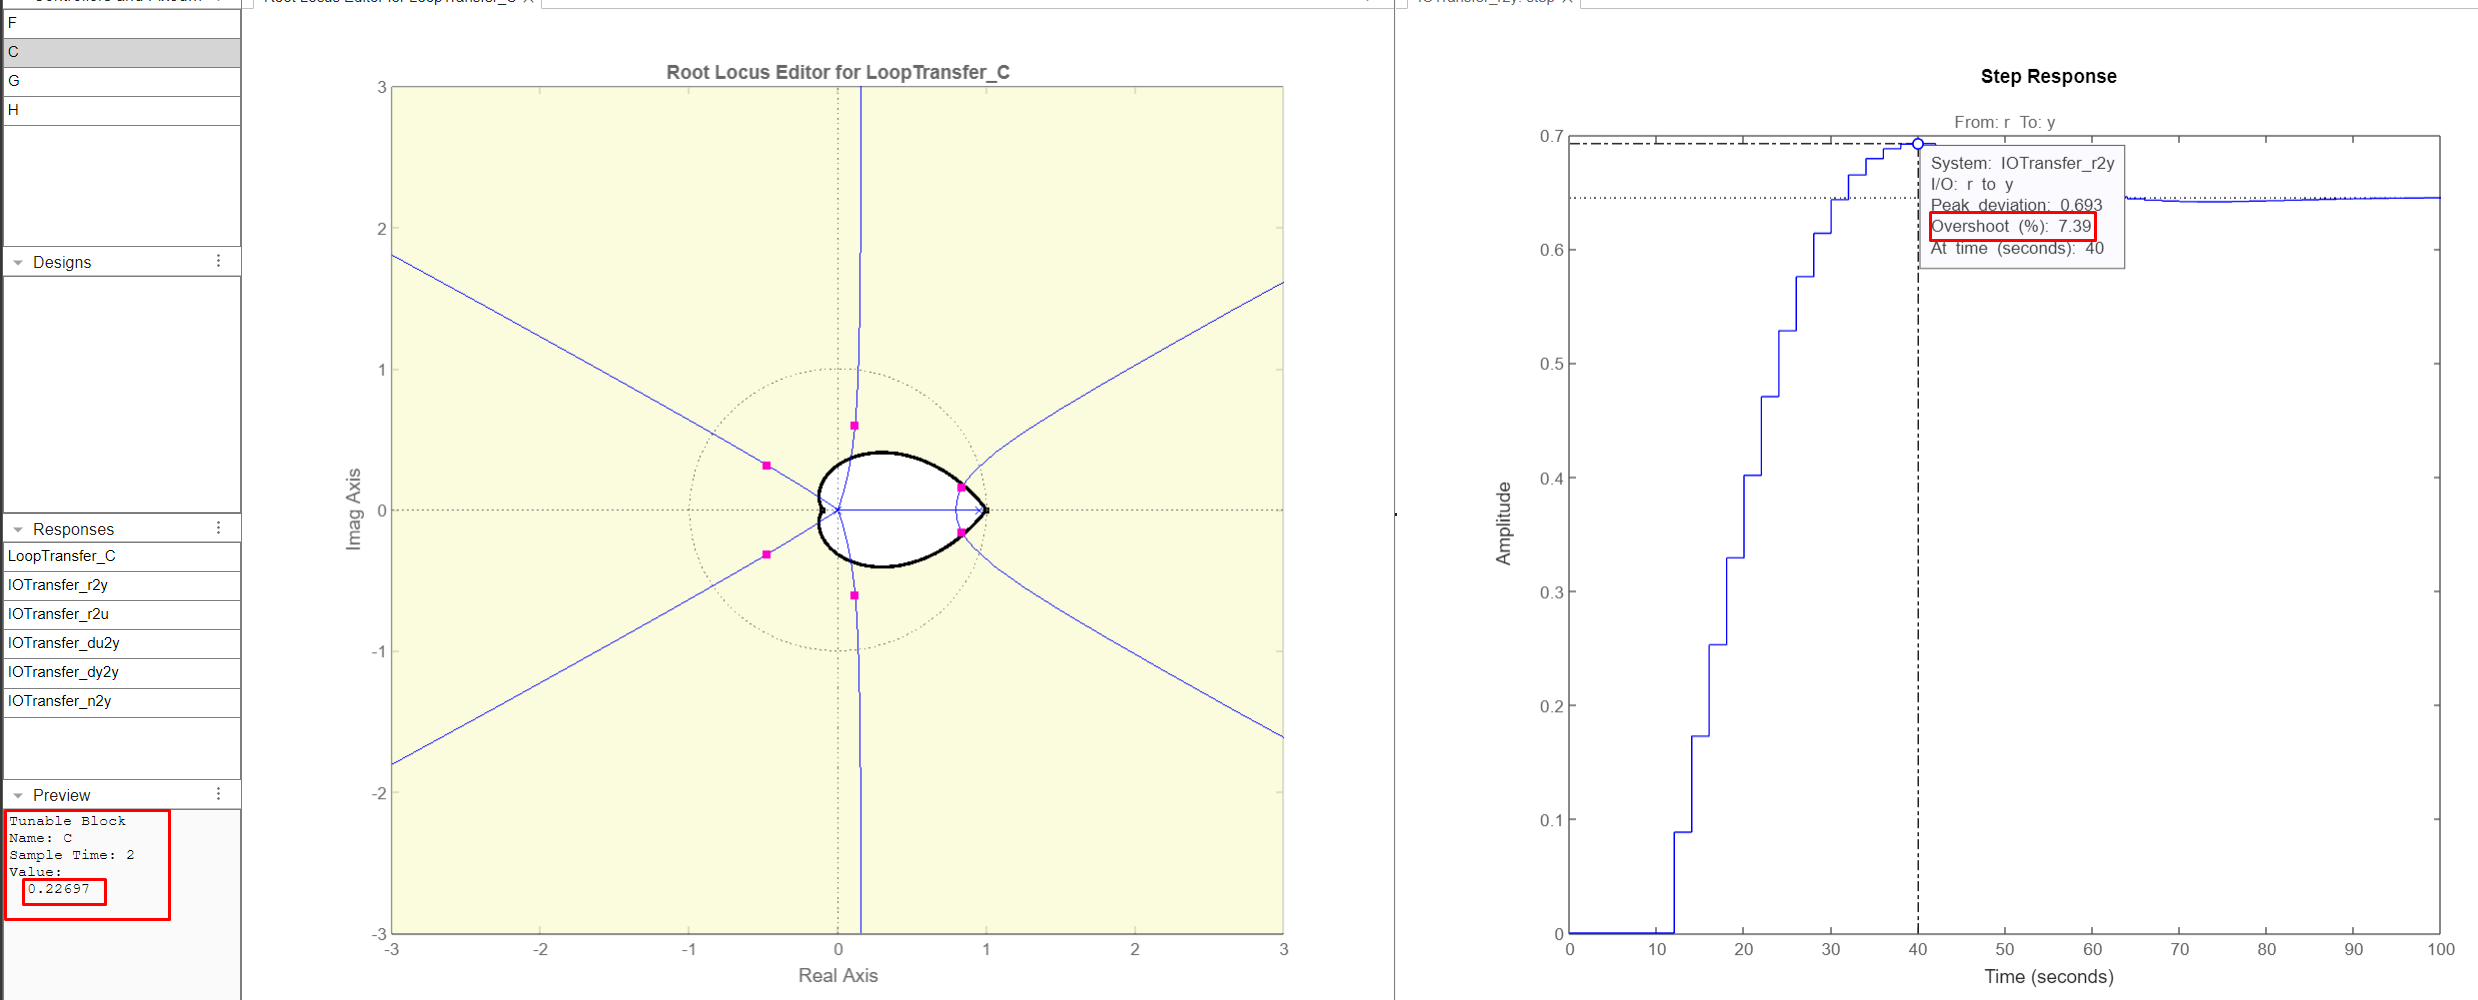

Dessa forma, é de fato essencial que *K* seja menor que 0.25 para manter a resposta com UP menor ou igual a 10%.

Para K < 0, temos:

Vamos utilizar a função `rltool` na função de transferência discreta e adicionar como requisito que o UP seja menor ou igual a 10%. Como podemos observar, as últimas raizes que estão na região branca restrita do gráfico têm UP menor ou igual a 10%. 

Para encontrar o maior valor de K que apresente esse requisito, vamos posicionar os últimos polos em cima da borda. Isso fará com que a resposta tenha UP menor ou igual a 10%. Em seguida, determinaremos o menor valor de *K* que a função tem UP menor ou igual do que 10%:

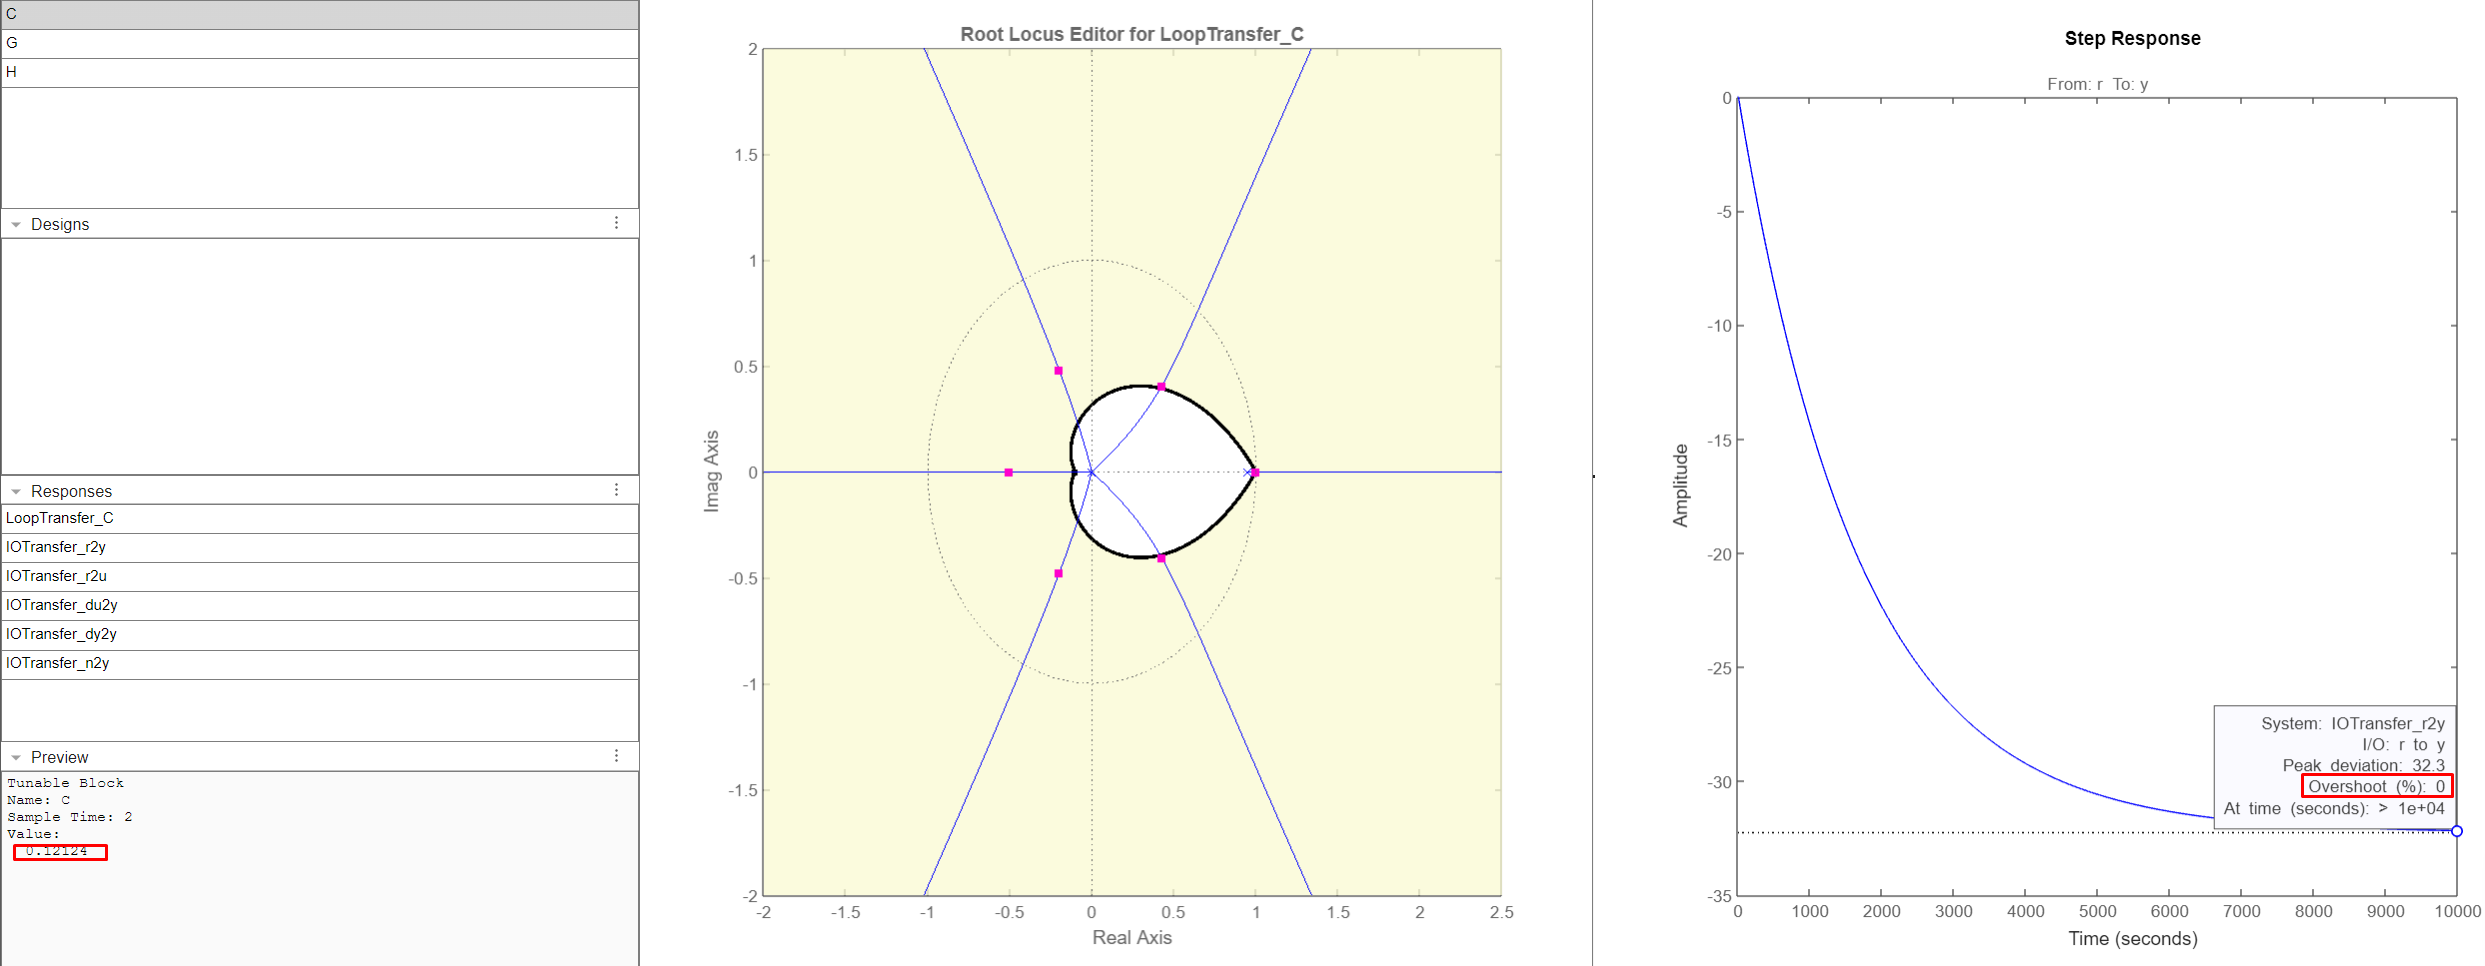

Como pode ser observado acima, quando os polos do lado direito está sobre a área definida, *K* assume um valor de -0.12 e a resposta tem um UP de 0% que é menor que 10%.

Portanto, *K* precisa ser maior ou igual que -0.12 para ter um UP menor ou igual que 10%. Um exemplo está demonstrado abaixo com *K*= -0.14, o qual é próximo a -0.12. Com este valor de *K*, o tem um UP maior que 10%. 

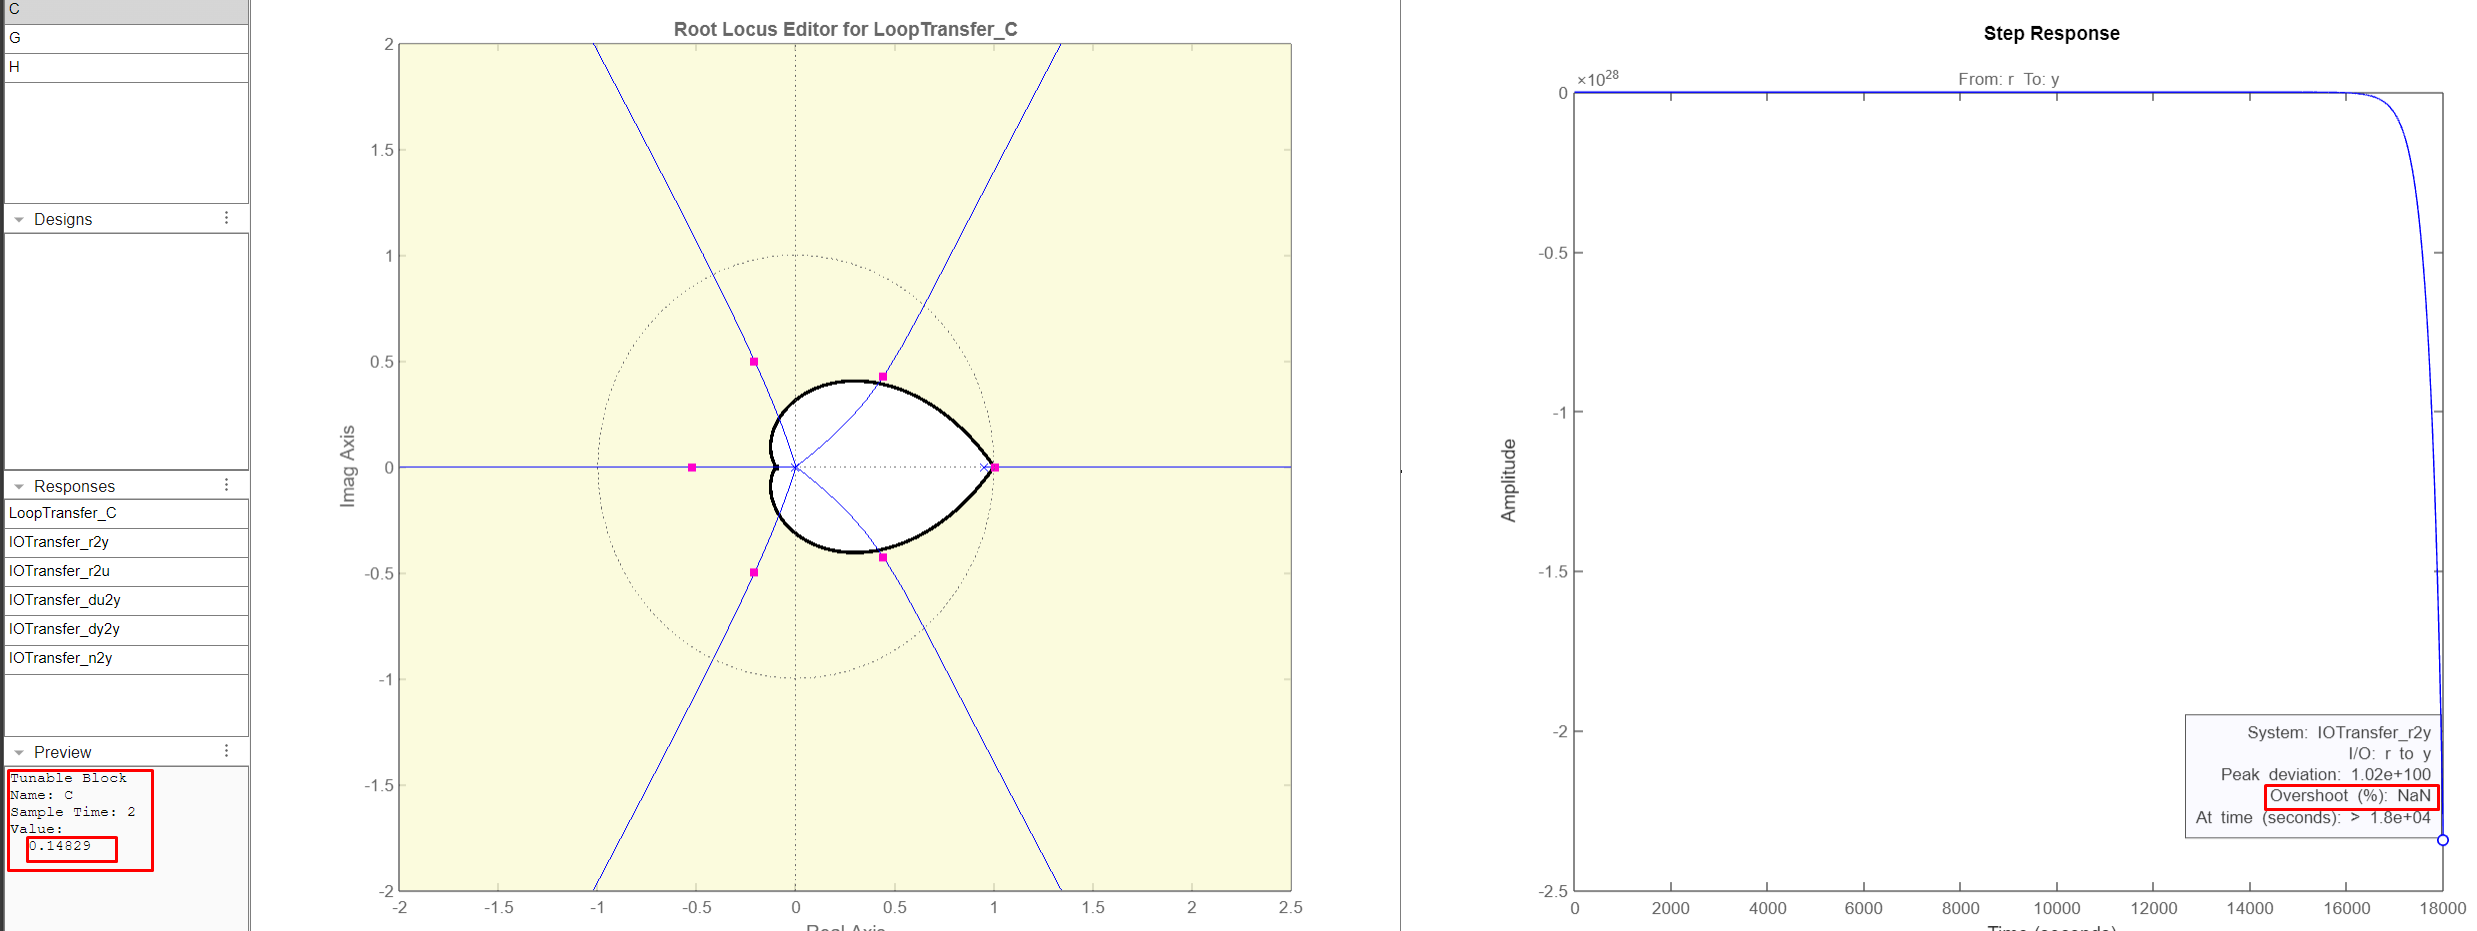

Dessa forma, é de fato essencial que *K* seja maior ou igual a -0.12 para manter a resposta com UP menor ou igual a 10%.

3.4 Verificando se existe valores de K para os quais $t_s\leq 10I$s:

ts = 10*I

ts = 140

Para K > 0, temos:

Vamos utilizar a função `rltool` na função de transferência discreta e adicionar como requisito que o ts seja menor ou igual a 140s. Como podemos observar, todas as raizes que estão na região branca restrita do gráfico têm ts menor ou igual a 140 s. 

Para encontrar o maior valor de K que apresente esse requisito, vamos posicionar os primeiro polos bem próximo da borda. Isso fará com que a resposta, que antes tinha ts menor ou igual a 140s, não tenha mais. Em seguida, determinaremos o primeiro valor de *K* que a função pode ter para ter ts maior do que 140s:

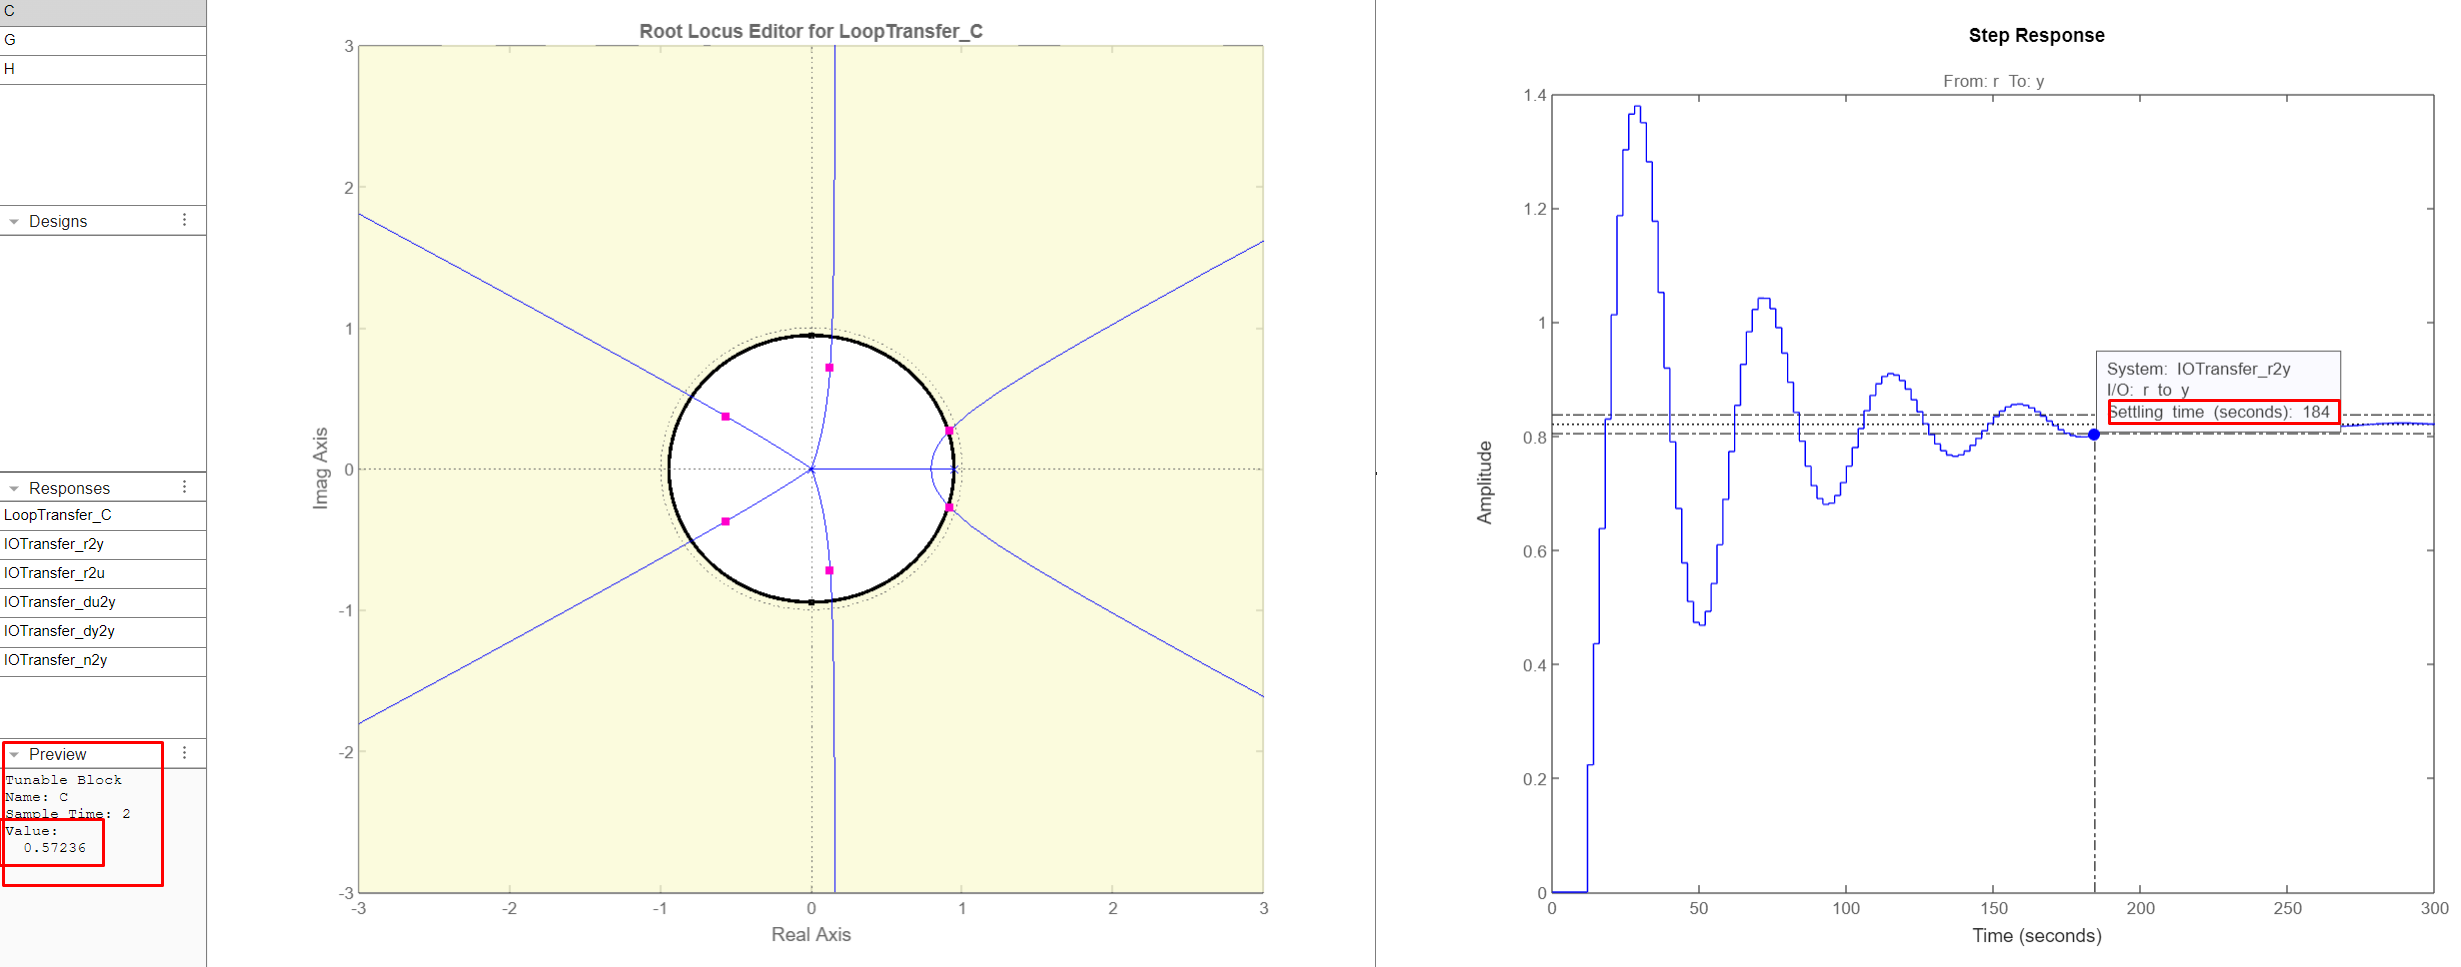

Como pode ser observado acima, quando os polos do lado direito está sobre a área definida, *K* assume um valor de 0.57 e a resposta tem um ts de 184s que é maior que 140s.

Portanto, *K* precisa ser menor que 0.57 para ter um ts menor que 140s. Um exemplo está demonstrado abaixo com *K*= 0.48, o qual é próximo a 0.57. Com este valor de *K*, o tem um ts menor que 140s. 

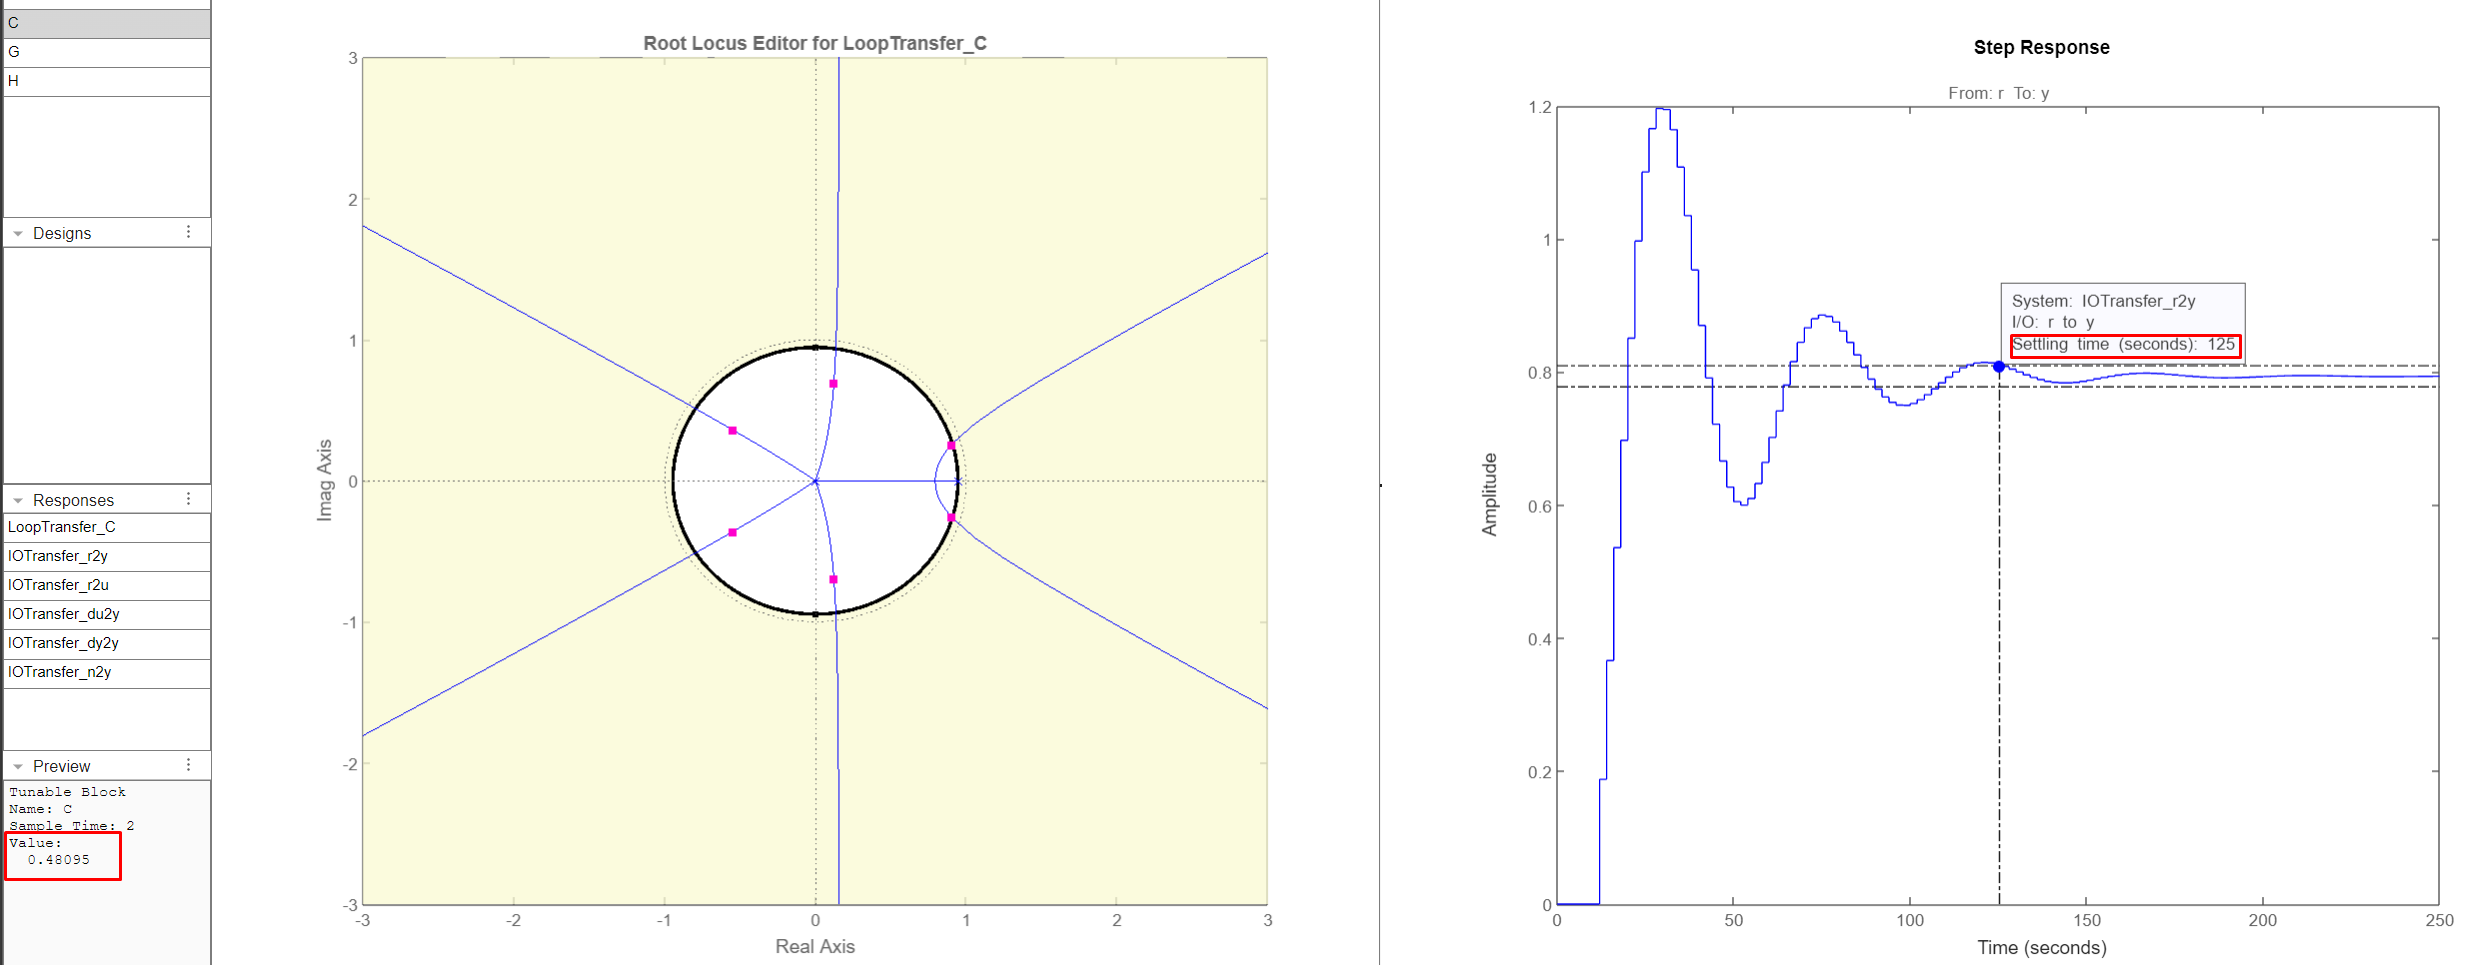

Dessa forma, é de fato essencial que *K* seja menor que 0.57 para manter a resposta com ts menor ou igual a 140s.

Para K < 0, temos:

Não existe K que faça o ts ser menor ou igual a 140s. Isso porque o polo do semiplano direito está muito longe da origem. Então, ele é lento e o menor valor de ts que consegue é de 166s. 

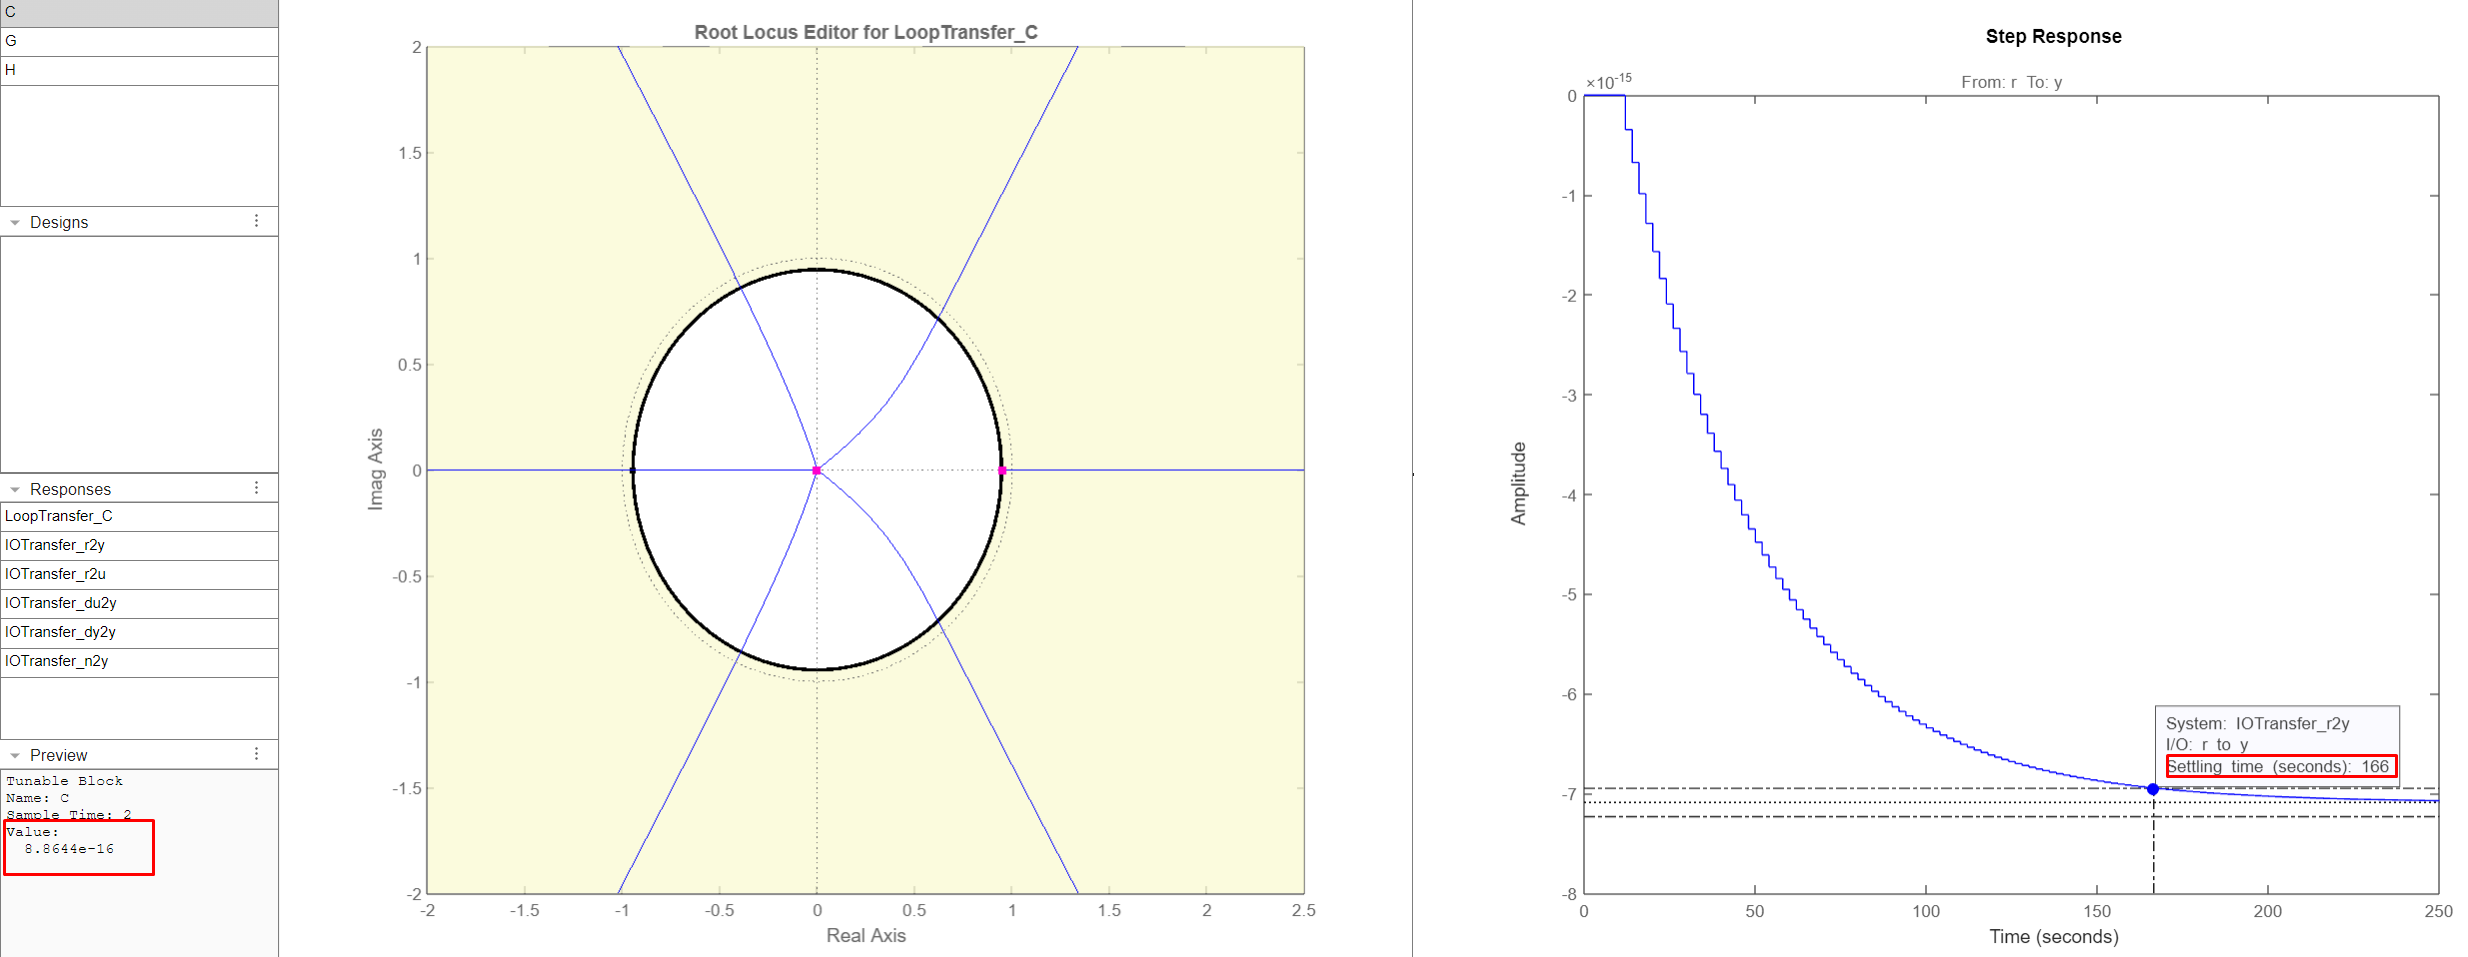

Dessa forma, é de fato essencial que *K* seja maior ou igual a -0.12 para manter a resposta com UP menor ou igual a 10%.

rltool(-G3z)

Lembrando:  $\zeta =\cos \;\theta$ ,  $\textrm{ts}=\frac{4}{\zeta \omega_n }$, $0<\zeta <0\ldotp 9$.

**Atividade 4: Seja o diagrama de blocos mostrado. **

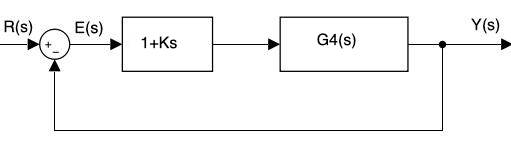

6.1 Faça o LR e explique o efeito de K sobre os polos de malha fechada.

6.2 Obtenha os valores de $K>0$ para os quais o sistema é estável.

6.3 Obtenha um valor de K tal que $UP\leq 10\%$ e o tempo de estabelecimento seja o menor possível. Faça uma simulação ao degrau comprovando.

Respostas:

6.1 Faça o LR e explique o efeito de K sobre os polos de malha fechada:

Temos: $1+KG_4(s)=0$

Ao fechar a malha, encontramos Ks e não apenas o K.

Por isso, é preciso multiplicar s por G4(s) para obter a equação da definição:

G4

G4 =
 
                   1200
  ---------------------------------------
  s^4 + 40 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.
Model Properties


s = tf('s');
G4s = G4 * s

G4s =
 
                  1200 s
  ---------------------------------------
  s^4 + 40 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.
Model Properties


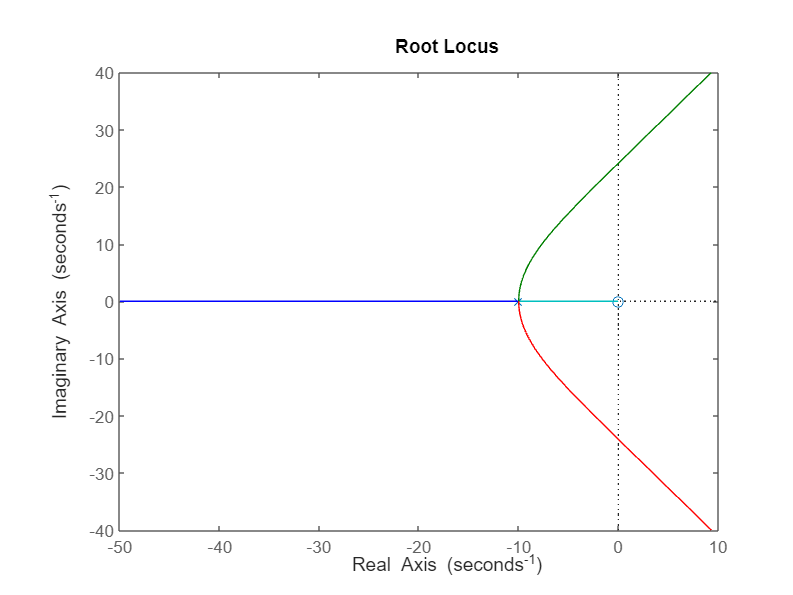

rlocus(G4s)

rltool(G4s)

Conforme o K vai crescendo, os polos vou aumentando para as suas respectivas assintotas ou faixas.

Um polo vai para menos infinito, outros 2 vão para duas assintotas diferentes e o último tende para zero.

6.2 Obtenha os valores de $K>0$ para os quais o sistema é estável.

Para K > 0, temos:

O sistema é estável quando parte real do número é negativa. Então, a raiz não poderia passar para o semiplano direito:

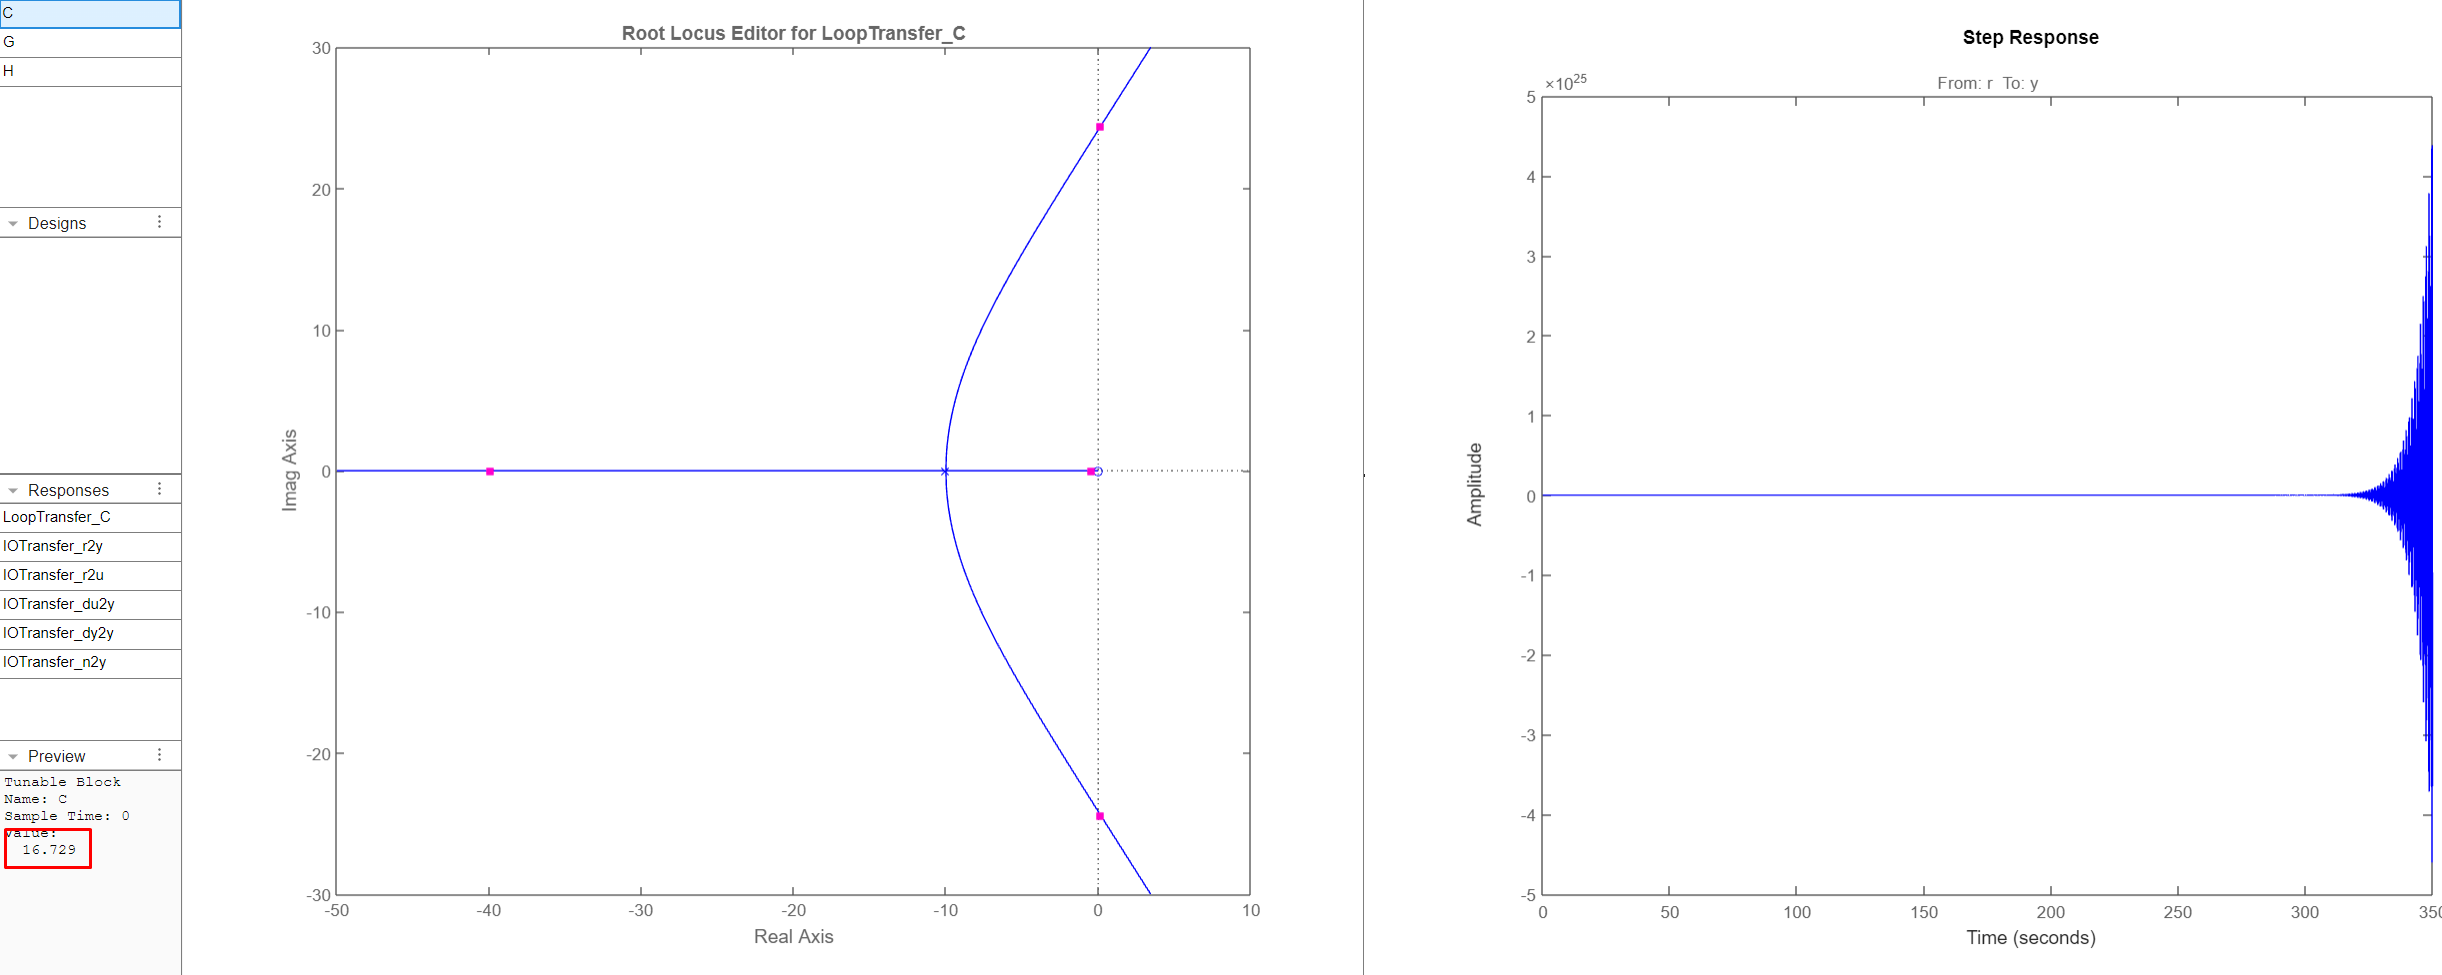

Como pode ser observado acima, quando os polos passam para o semiplano direito estão sobre o círculo unitário, *K* assume um valor de 16 e a resposta se torna instável.

Portanto, *K* precisa ser menor que 16 para garantir a estabilidade. Um exemplo está demonstrado abaixo com *K*=15.9, o qual é próximo a 16. Com este valor de *K*, o sistema se estabiliza. 

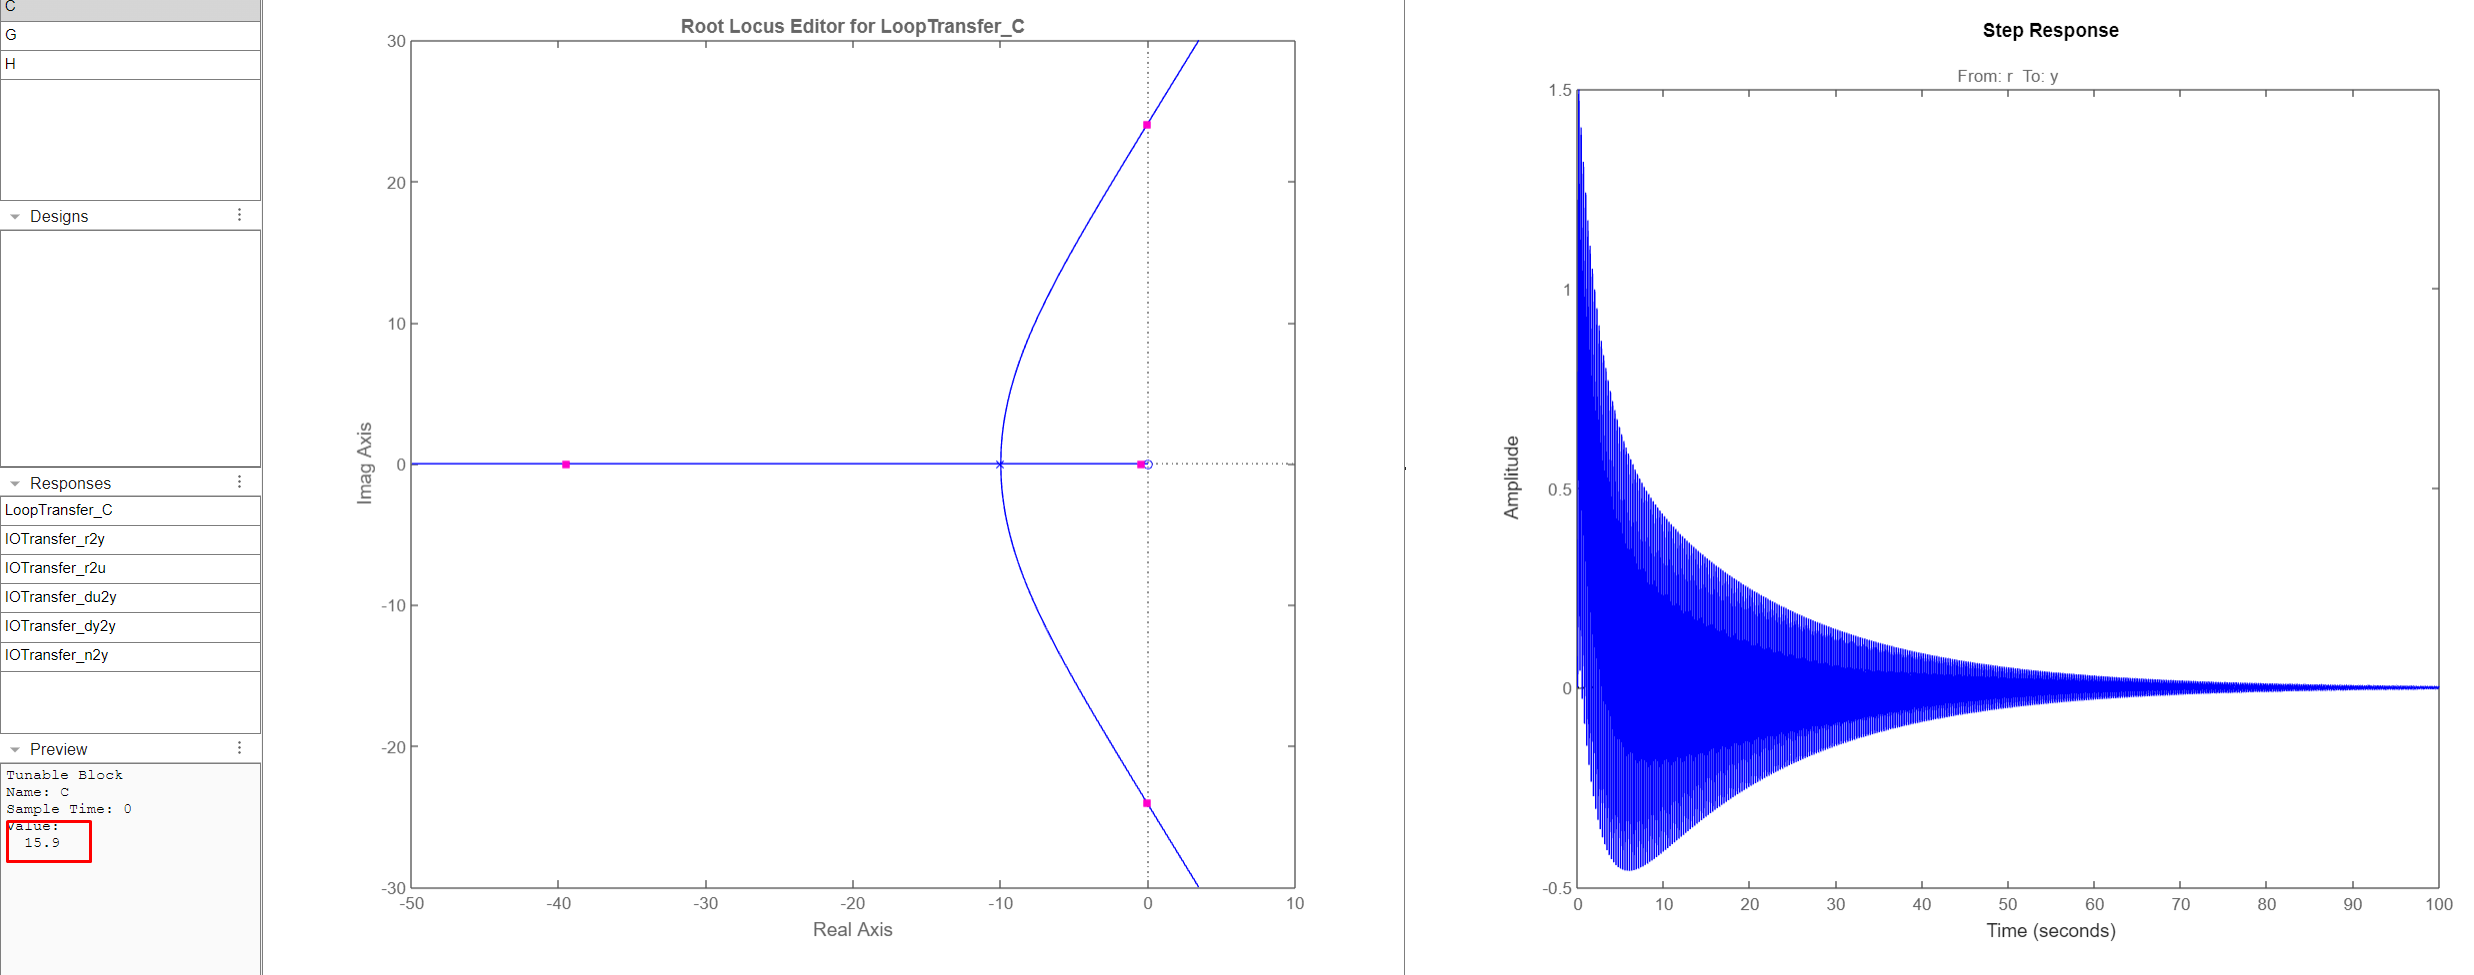

Dessa forma, é de fato essencial que *K* seja inferior a 16 para manter a estabilidade do sistema.

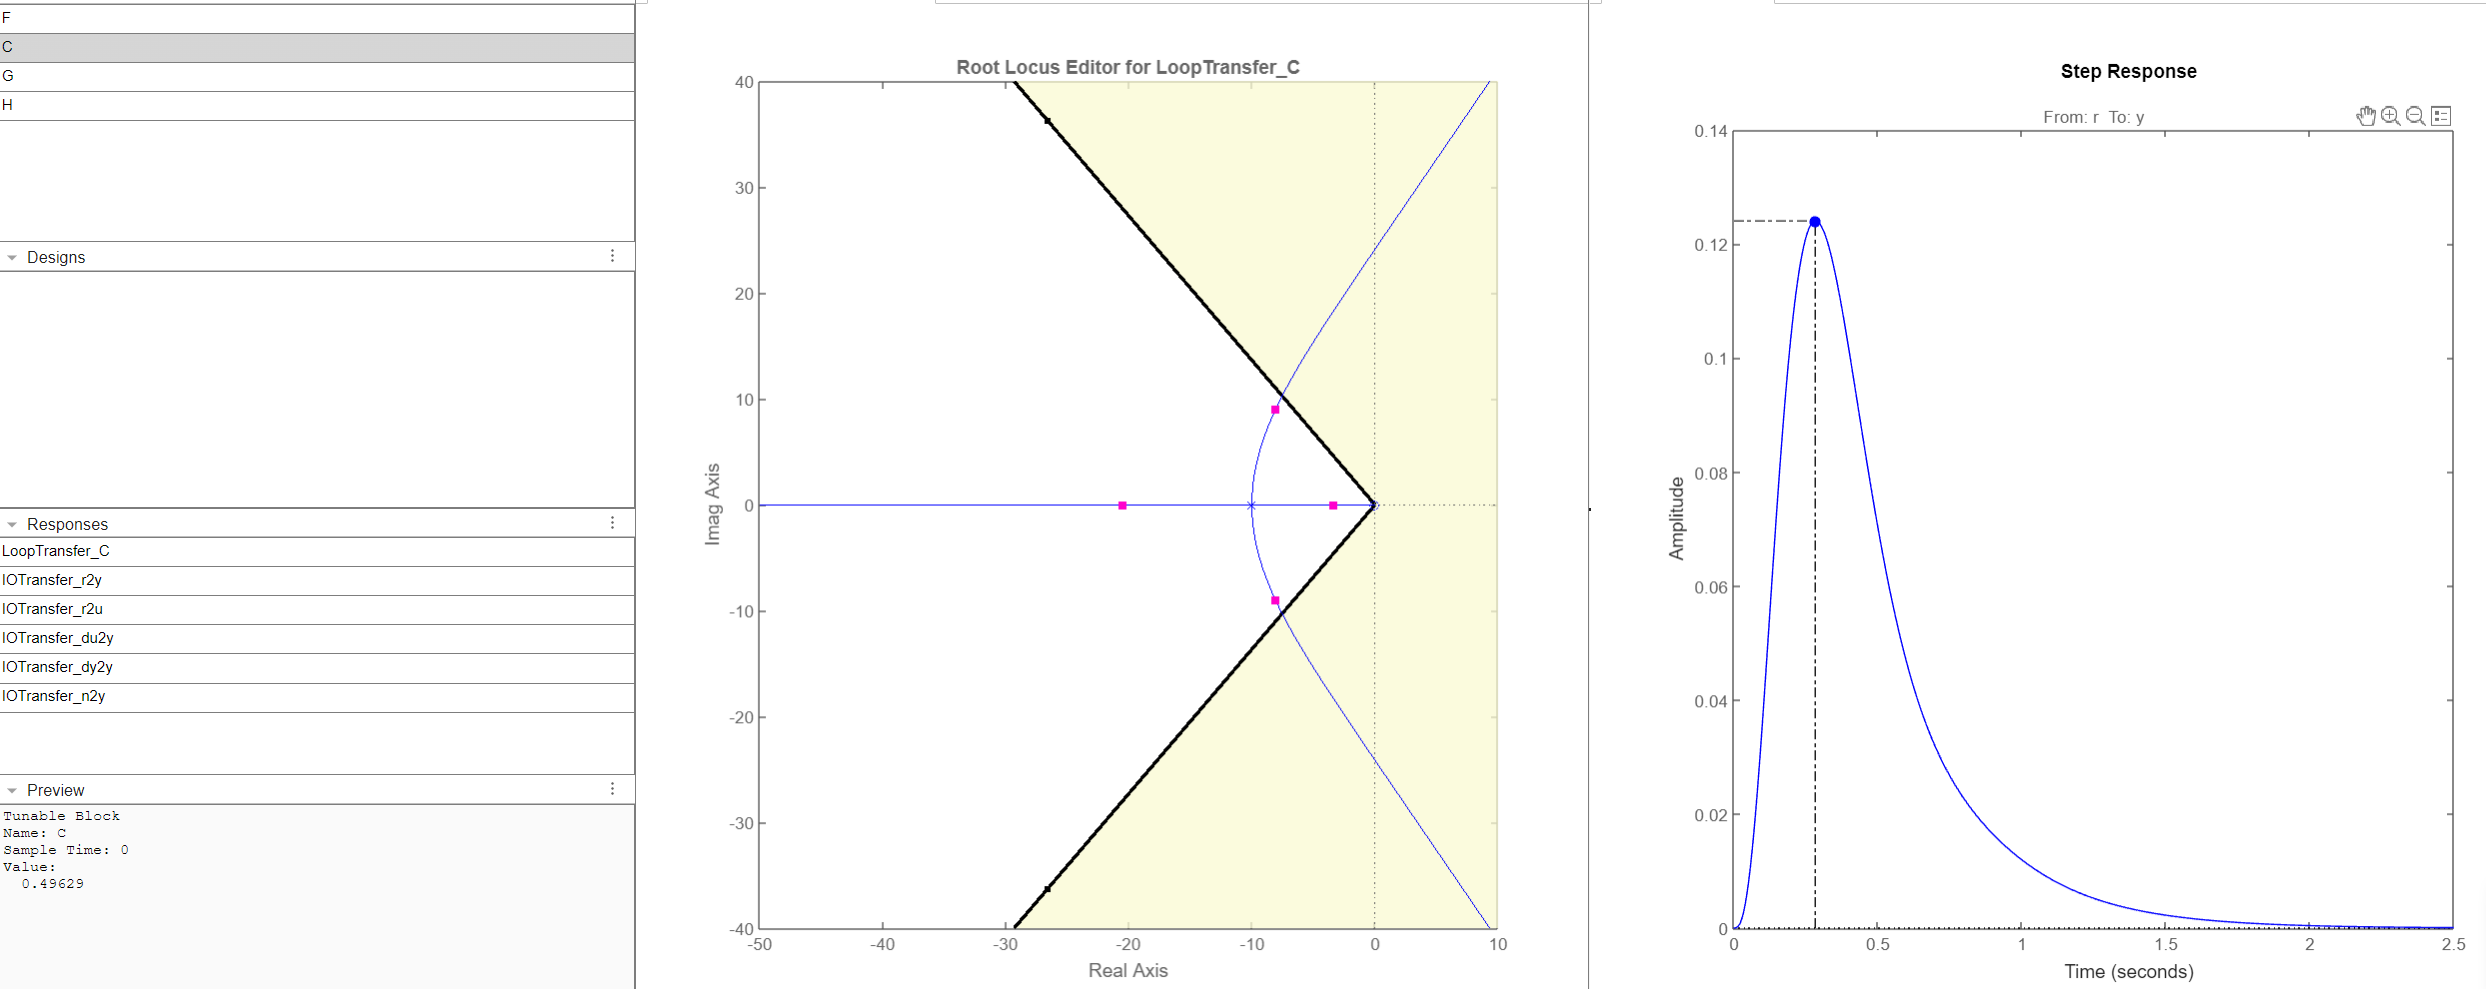

O maior K seria 0.49 como pode ver.

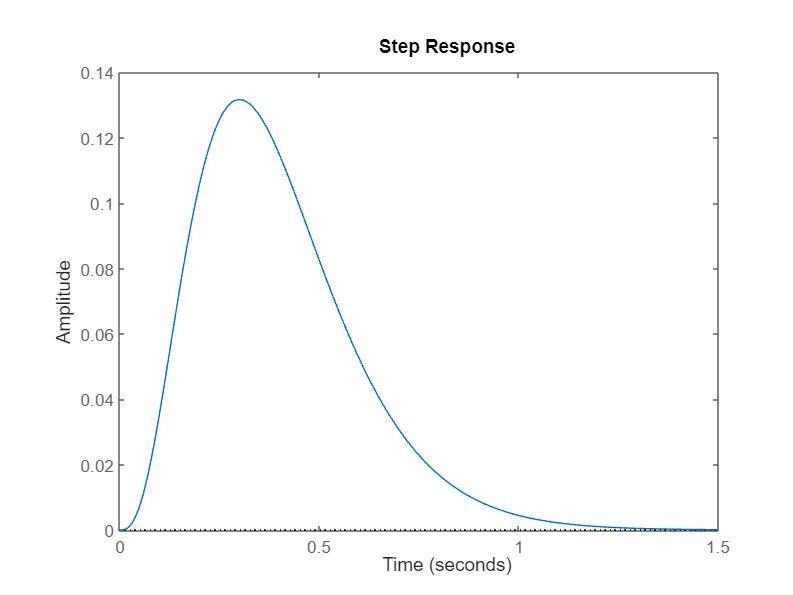

step(G4s*0.49)